# Figure 2 UMAP projections

Code for UMAP projections in Figure 2, supplementary figure 13 (female group1), supplementary figure 5 (projection color coded according to acoustic group), and sup figure 3 (projection color coded according to some acoustic features)

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'BatID')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood','RMS_mean', 'Sal_mean', 'F0_mean','Q1Mic_mean');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'TmicAll7','MPSmicReduction4Clustering', 'MedianSilhouette', 'MeanSilhouette') % obtained from DeafBats_CatCalls8.mlx
load(fullfile(LocalDataDir, 'DeafBats_PCA_MaleAcGroup5.mat'), 'Score_M')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleAcGroup5.mat'), 'NPC_opt_M', 'EigenVec_DFA_M')
load(fullfile(LocalDataDir, 'DeafBats_PCA_FemaleAcGroup1.mat'), 'Score_F')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_FemaleAcGroup1.mat'), 'NPC_opt_F', 'EigenVec_DFA_F')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get color vectors ready

% Get the color vector ready for BatName, Sex and Deafness
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

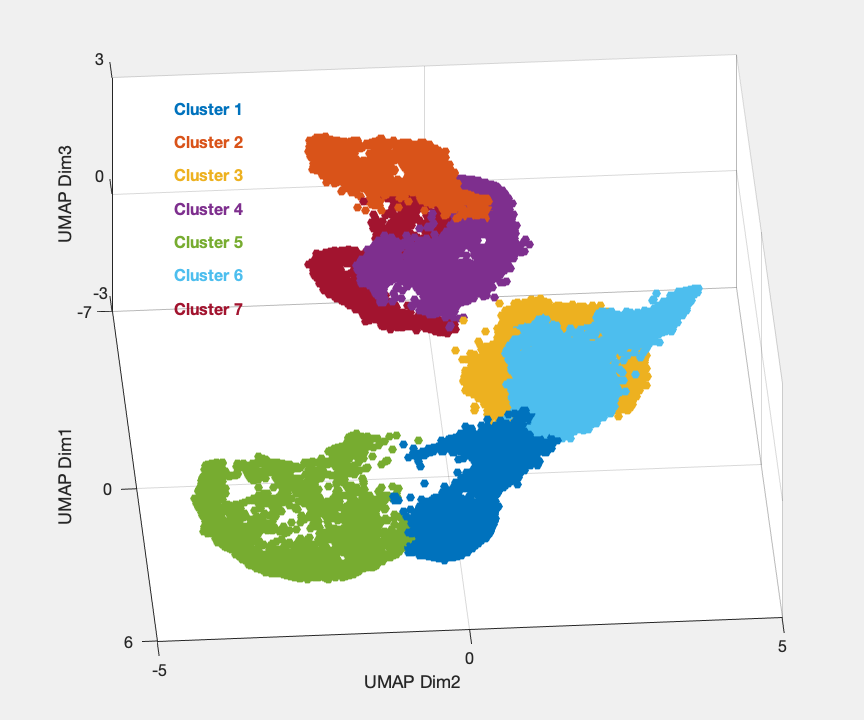

NGroups = length(unique(TmicAll7));
Fig1 = figure(1);
clf
set(gcf,'Visible','on');
scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,ColorCode(TmicAll7,:,:),'filled', 'o');
xlabel('UMAP Dim1', 'FontSize',8);
ylabel('UMAP Dim2', 'FontSize',8);
zlabel('UMAP Dim3', 'FontSize',8);
XLim = get(gca, 'XLim');
XLim = [floor(XLim(1)) ceil(XLim(2))];
set(gca, 'XLim', XLim);
YLim = get(gca, 'YLim');
YLim = [-5 ceil(YLim(2))];
set(gca, 'YLim', YLim);
ZLim = get(gca, 'ZLim');
ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',8);
% title('UMAP Projection of Mic MPS (Color = Acoustic clusters) with Nneighbors = 10 and MinDist = 0.051')
for gg=1:NGroups
    text(-7,-4, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold', 'FontSize',8 );
end
% view([68.50 26.52])
view([-31.4911    9.2096])
view([85.8723   54.7871])
Fig1.Units = 'inches';
Fig1.Position(3:4) = [6 5];
Fig1.PaperSize = [6 5];

print(Fig1,fullfile(Path2Paper,'Figure2_UMAP_AcGroups.pdf'),'-dpdf','-fillpage')

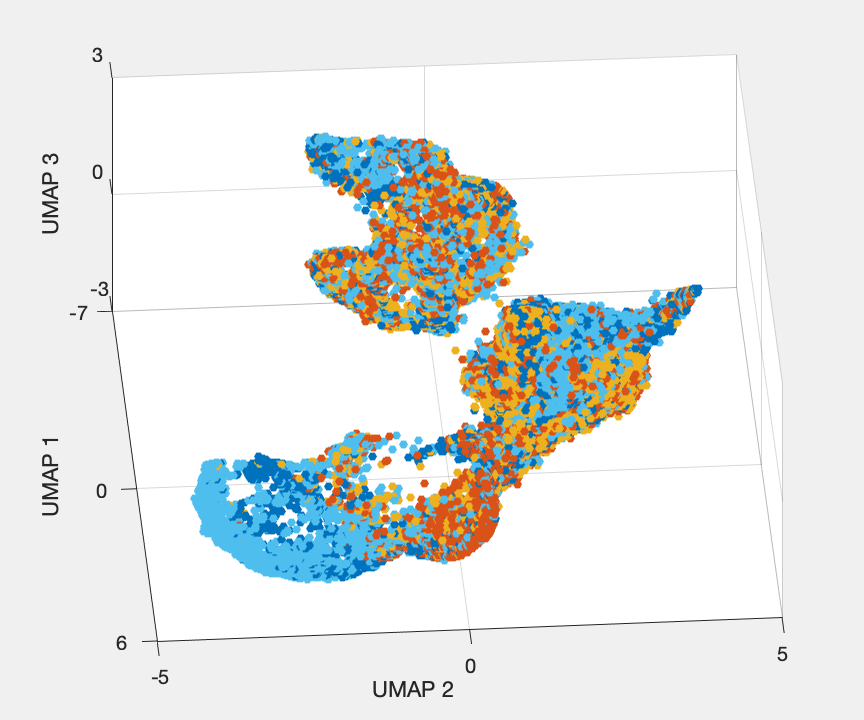

Fig2 = figure(2);
clf
set(gcf,'Visible','on')
scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,CSexDeaf(MicAudioGood01,:),'filled')
% hold on
% scatter3(MPSmicReduction4Clustering(TmicAll7==5,1), MPSmicReduction4Clustering(TmicAll7==5,2),MPSmicReduction4Clustering(TmicAll7==5,3),20,'MarkerEdgeColor','k')
% hold on
% scatter3(MPSmicReduction4Clustering(TmicAll7==1,1), MPSmicReduction4Clustering(TmicAll7==1,2),MPSmicReduction4Clustering(TmicAll7==1,3),20,'MarkerEdgeColor',[0.5 0.5 0.5])
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
XLim = get(gca, 'XLim');
XLim = [floor(XLim(1)) ceil(XLim(2))];
set(gca, 'XLim', XLim);
YLim = get(gca, 'YLim');
YLim = [-5 ceil(YLim(2))];
set(gca, 'YLim', YLim);
ZLim = get(gca, 'ZLim');
ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
% title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% for ct=1:10
%     text(0,5,ZLim(2)-diff(ZLim)*ct/10, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold', 'FontSize',8)
% end
hold off
% view([68.50 26.52])
% view([-31.4911    9.2096])
view([85.8723   54.7871])
Fig2.Units = 'inches';
Fig2.Position(3:4) = [6 5];
Fig2.PaperSize = [6 5];

print(Fig2,fullfile(Path2Paper,'Figure2_UMAP_SexDeaf.pdf'),'-dpdf','-fillpage')

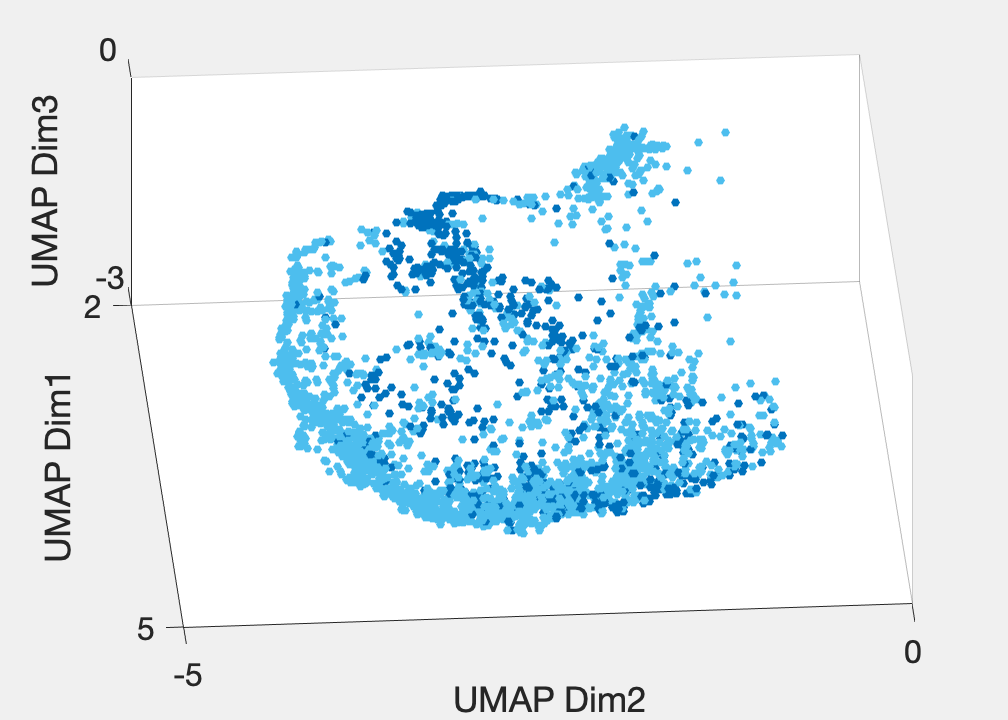

Fig3 = figure(3);
clf
SexDeafMic = SexDeaf(MicAudioGood01);
IndMicAudioGood = find(MicAudioGood01);
G5M = logical((TmicAll7==5).*contains(SexDeafMic,'M'));
set(gcf,'Visible','on')
SC3 = scatter3(MPSmicReduction4Clustering(G5M,1), MPSmicReduction4Clustering(G5M,2),MPSmicReduction4Clustering(G5M,3),20,CSexDeaf(IndMicAudioGood(G5M),:),'filled');
xlabel('UMAP Dim1', 'FontSize',16);
ylabel('UMAP Dim2', 'FontSize',16);
zlabel('UMAP Dim3', 'FontSize',16);
XLim = get(gca, 'XLim');
XLim = [2 ceil(XLim(2))];
set(gca, 'XLim', XLim);
YLim = get(gca, 'YLim');
YLim = [floor(YLim(1)) ceil(YLim(2))];
set(gca, 'YLim', YLim);
ZLim = get(gca, 'ZLim');
ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) XLim(2)], 'XTickLabel', [XLim(1) XLim(2)],'ZTick', [ZLim(1) ZLim(2)], 'ZTickLabel', [ZLim(1) ZLim(2)],'YTick', [YLim(1) YLim(2)], 'YTickLabel', [YLim(1) YLim(2)], 'GridColor', [0 0 0], 'FontSize',16);
% title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% for ct=1:10
%     text(1,-4.5,ZLim(2)-diff(ZLim)*ct/10, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold', 'FontSize',8 )
% end
% view([68.50 26.52])
% view([-31.4911    9.2096])
view([85.8723   54.7871])
Fig3.Units = 'inches';
Fig3.Position(3:4) = [7 5];
Fig3.PaperSize = [7 5];

print(Fig3,fullfile(Path2Paper,'Figure2_UMAPG5M_SexDeaf.pdf'),'-dpdf','-fillpage')

Obtain projection values of calls in DF1 space (cannonical values)

Canon = (Score_M(:,1:NPC_opt_M) - repmat(mean(Score_M(:,1:NPC_opt_M)),size(Score_M,1),1)) * EigenVec_DFA_M(:,1);

Now plot the male calls of Acoustic group 5 colorcoded according to Canon

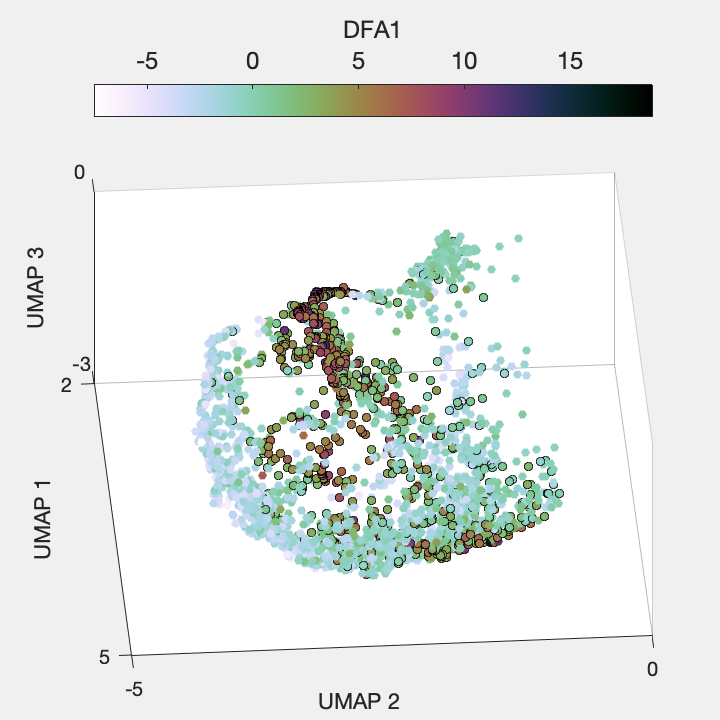

x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(Canon,x);
Fig4 = figure(4);
clf
SexDeafMic = SexDeaf(MicAudioGood01);
IndMicAudioGood = find(MicAudioGood01);
G5M = logical((TmicAll7==5).*contains(SexDeafMic,'M'));
G5MD = logical((TmicAll7==5).*contains(SexDeafMic,'DM'));
set(gcf,'Visible','on')
Tbl = table(MPSmicReduction4Clustering(G5M,1),MPSmicReduction4Clustering(G5M,2),MPSmicReduction4Clustering(G5M,3),Canon, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','DFA1'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','DFA1', 'SizeData',20);
% SC3 = scatter3(MPSmicReduction4Clustering(G5M,1), MPSmicReduction4Clustering(G5M,2),MPSmicReduction4Clustering(G5M,3),10,Colors,'filled');
% SC3.CData = CSexDeaf(IndMicAudioGood(G5M),:);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
% view([68.50 26.52])
% view([-31.4911    9.2096])
view([85.8723   54.7871])
cc=colorbar();
colormap(GRAD)
cc.Label.String = 'DFA1';
cc.FontSize = 12;
cc.Location = 'northoutside';
hold on
SexDeafMicG5M = SexDeafMic(G5M);
Tbl = table(MPSmicReduction4Clustering(G5MD,1),MPSmicReduction4Clustering(G5MD,2),MPSmicReduction4Clustering(G5MD,3),Canon(contains(SexDeafMicG5M, 'D')), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','DFA1'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','MarkerEdgeColor','k', 'SizeData',20);

% YTL = [-10 0 10 20]; % Set which label we want to see in kHz
% YT_new = (YTL + Slide)*10^x / ceil((MaxColVal+Slide)*10^x);
% set(cc, 'YTickLabel',YTL,'YTick',YT_new)
XLim = get(gca, 'XLim');
XLim = [2 ceil(XLim(2))];
set(gca, 'XLim', XLim);
YLim = get(gca, 'YLim');
YLim = [floor(YLim(1)) ceil(YLim(2))];
set(gca, 'YLim', YLim);
ZLim = get(gca, 'ZLim');
ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) XLim(2)], 'XTickLabel', [XLim(1) XLim(2)],'ZTick', [ZLim(1) ZLim(2)], 'ZTickLabel', [ZLim(1) ZLim(2)],'YTick', [YLim(1) YLim(2)], 'YTickLabel', [YLim(1) YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
% title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% for ct=1:10
%     text(1,-4.5,ZLim(2)-diff(ZLim)*ct/10, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold', 'FontSize',8 )
% end
hold off
Fig4.Units = 'inches';
Fig4.Position(3:4) = [5 5];
Fig4.PaperSize = [5 5];

print(Fig4,fullfile(Path2Paper,'Figure2_UMAPG5M_DFA1.pdf'),'-dpdf','-fillpage')

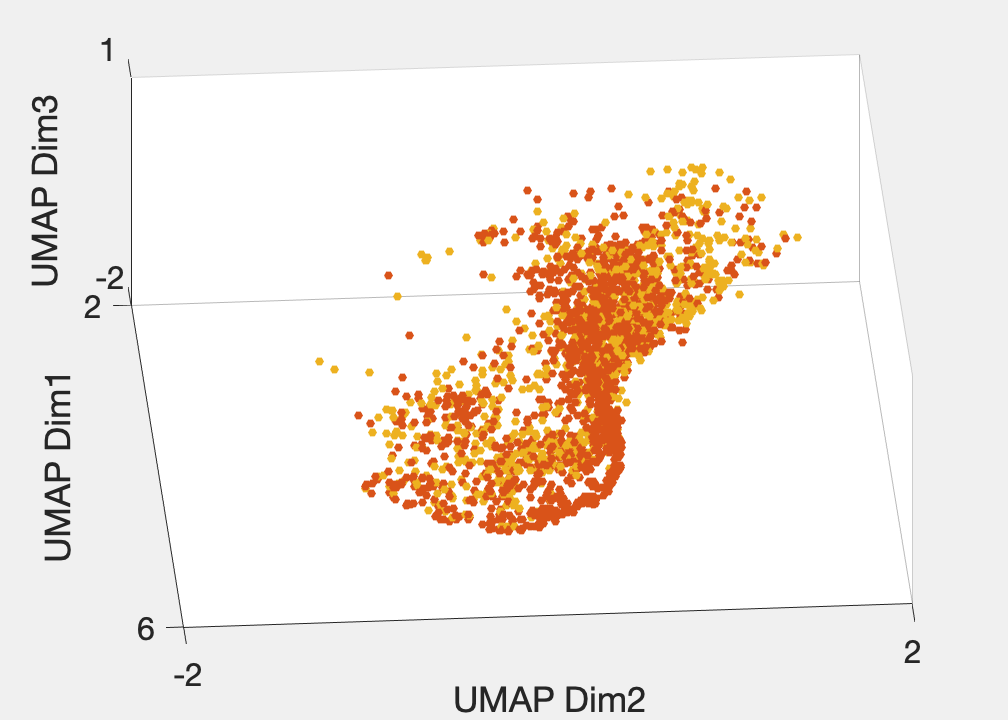

Fig5 = figure(5);
clf
SexDeafMic = SexDeaf(MicAudioGood01);
IndMicAudioGood = find(MicAudioGood01);
G1F = logical((TmicAll7==1).*contains(SexDeafMic,'F'));
set(gcf,'Visible','on')
SC3 = scatter3(MPSmicReduction4Clustering(G1F,1), MPSmicReduction4Clustering(G1F,2),MPSmicReduction4Clustering(G1F,3),20,CSexDeaf(IndMicAudioGood(G1F),:),'filled');
xlabel('UMAP Dim1', 'FontSize',16);
ylabel('UMAP Dim2', 'FontSize',16);
zlabel('UMAP Dim3', 'FontSize',16);
XLim = get(gca, 'XLim');
XLim = [floor(XLim(1)) ceil(XLim(2))];
set(gca, 'XLim', XLim);
YLim = get(gca, 'YLim');
YLim = [floor(YLim(1)) ceil(YLim(2))];
set(gca, 'YLim', YLim);
ZLim = get(gca, 'ZLim');
ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) XLim(2)], 'XTickLabel', [XLim(1) XLim(2)],'ZTick', [ZLim(1) ZLim(2)], 'ZTickLabel', [ZLim(1) ZLim(2)],'YTick', [YLim(1) YLim(2)], 'YTickLabel', [YLim(1) YLim(2)], 'GridColor', [0 0 0], 'FontSize',16);
% title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% for ct=1:10
%     text(1,-4.5,ZLim(2)-diff(ZLim)*ct/10, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold', 'FontSize',8 )
% end
% view([68.50 26.52])
% view([-31.4911    9.2096])
view([85.8723   54.7871])
Fig5.Units = 'inches';
Fig5.Position(3:4) = [7 5];
Fig5.PaperSize = [7 5];

print(Fig5,fullfile(Path2Paper,'Figure2_UMAPG1F_SexDeaf.pdf'),'-dpdf','-fillpage')

Obtain projection values of calls in DF1 space (cannonical values)

Canon = (Score_F(:,1:NPC_opt_F) - repmat(mean(Score_F(:,1:NPC_opt_F)),size(Score_F,1),1)) * EigenVec_DFA_F(:,1);

Now plot the male calls of Acoustic group 1 colorcoded according to Canon

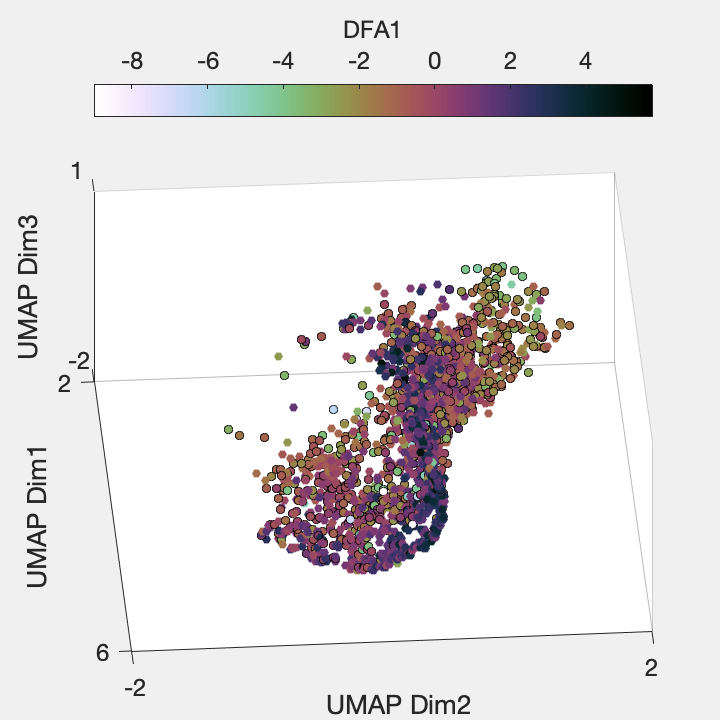

x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(Canon,x);
Fig6 = figure(6);
clf
SexDeafMic = SexDeaf(MicAudioGood01);
IndMicAudioGood = find(MicAudioGood01);
G1F = logical((TmicAll7==1).*contains(SexDeafMic,'F'));
G1FH = logical((TmicAll7==1).*contains(SexDeafMic,'HF'));
set(gcf,'Visible','on')
Tbl = table(MPSmicReduction4Clustering(G1F,1),MPSmicReduction4Clustering(G1F,2),MPSmicReduction4Clustering(G1F,3),Canon, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','DFA1'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','DFA1', 'SizeData',20);
% SC3 = scatter3(MPSmicReduction4Clustering(G5M,1), MPSmicReduction4Clustering(G5M,2),MPSmicReduction4Clustering(G5M,3),10,Colors,'filled');
% SC3.CData = CSexDeaf(IndMicAudioGood(G5M),:);
xlabel('UMAP Dim1', 'FontSize',12);
ylabel('UMAP Dim2', 'FontSize',12);
zlabel('UMAP Dim3', 'FontSize',12);
% view([68.50 26.52])
% view([-31.4911    9.2096])
view([85.8723   54.7871])
cc=colorbar();
colormap(GRAD)
cc.Label.String = 'DFA1';
cc.FontSize = 12;
cc.Location = 'northoutside';
hold on
SexDeafMicG1F = SexDeafMic(G1F);
Tbl = table(MPSmicReduction4Clustering(G1FH,1),MPSmicReduction4Clustering(G1FH,2),MPSmicReduction4Clustering(G1FH,3),Canon(contains(SexDeafMicG1F, 'H')), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','DFA1'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','MarkerEdgeColor','k', 'SizeData',20);

% YTL = [-10 0 10 20]; % Set which label we want to see in kHz
% YT_new = (YTL + Slide)*10^x / ceil((MaxColVal+Slide)*10^x);
% set(cc, 'YTickLabel',YTL,'YTick',YT_new)
XLim = get(gca, 'XLim');
XLim = [floor(XLim(1)) ceil(XLim(2))];
set(gca, 'XLim', XLim);
YLim = get(gca, 'YLim');
YLim = [floor(YLim(1)) ceil(YLim(2))];
set(gca, 'YLim', YLim);
ZLim = get(gca, 'ZLim');
ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) XLim(2)], 'XTickLabel', [XLim(1) XLim(2)],'ZTick', [ZLim(1) ZLim(2)], 'ZTickLabel', [ZLim(1) ZLim(2)],'YTick', [YLim(1) YLim(2)], 'YTickLabel', [YLim(1) YLim(2)], 'GridColor', [0 0 0], 'FontSize',12);
% title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))

% for ct=1:10
%     text(1,-4.5,ZLim(2)-diff(ZLim)*ct/10, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold', 'FontSize',8 )
% end
hold off
Fig6.Units = 'inches';
Fig6.Position(3:4) = [5 5];
Fig6.PaperSize = [5 5];

print(Fig6,fullfile(Path2Paper,'Figure2_UMAPG1F_DFA1.pdf'),'-dpdf','-fillpage')

UMAP projection with all data color coded by pitch saliency

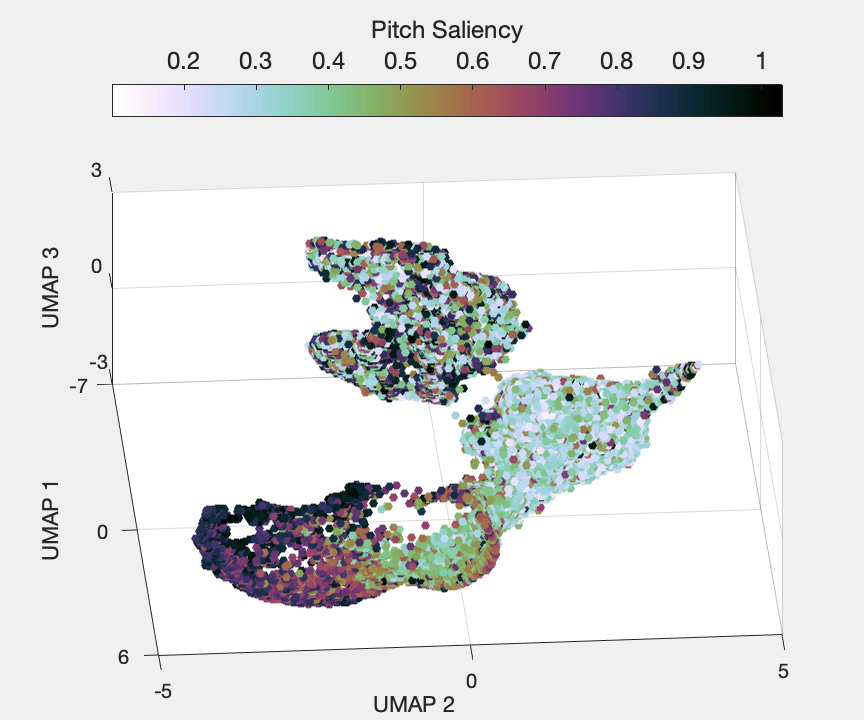

Fig7 = figure(7);
clf
set(gcf,'Visible','on')
x=2;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(Sal_mean,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),Sal_mean(MicAudioGood01), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','Saliency'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','Saliency', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
colormap(GRAD)
cc.Label.String = 'Pitch Saliency';
cc.FontSize = 12;
cc.Location = 'northoutside';

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig7.Units = 'inches';
Fig7.Position(3:4) = [6 5];
Fig7.PaperSize = [6 5];
print(Fig7,fullfile(Path2Paper,'SupFigure3_UMAP_PitchSaliency.pdf'),'-dpdf','-fillpage')

UMAP projection with all data color coded by First spectral quartile on Mic

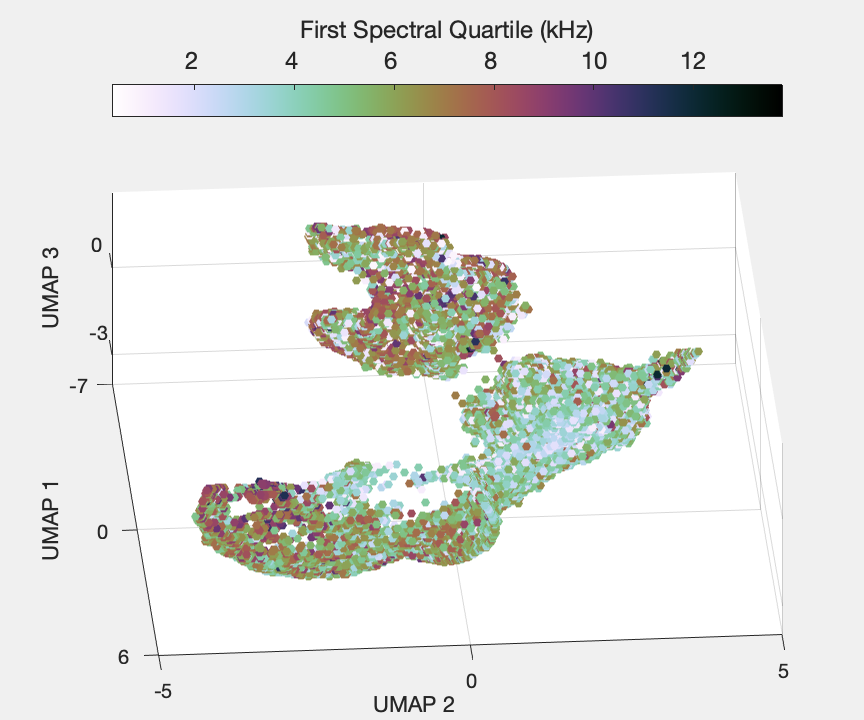

Fig8 = figure(8);
clf
set(gcf,'Visible','on')
x=0;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(Q1Mic_mean,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),Q1Mic_mean(MicAudioGood01), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','Q1Mic'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','Q1Mic', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
colormap(GRAD)
cc.Label.String = 'First Spectral Quartile (kHz)';
cc.FontSize = 12;
cc.Location = 'northoutside';
cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig8.Units = 'inches';
Fig8.Position(3:4) = [6 5];
Fig8.PaperSize = [6 5];
print(Fig8,fullfile(Path2Paper,'SupFigure3_UMAP_Q1Mic.pdf'),'-dpdf','-fillpage')

UMAP projection with all data color coded by RMS

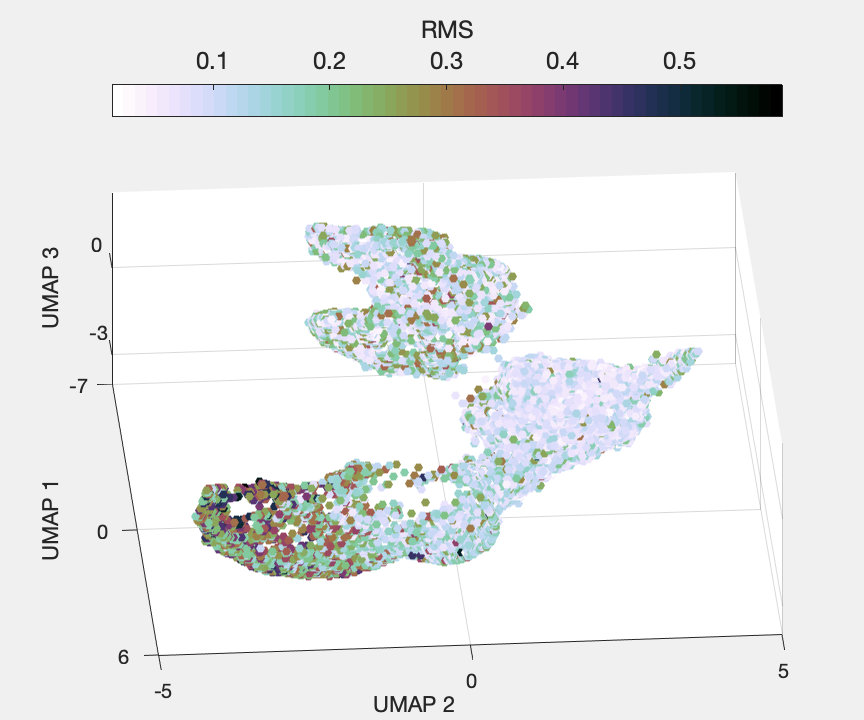

Fig9 = figure(9);
clf
set(gcf,'Visible','on')
x=2;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(RMS_mean,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),RMS_mean(MicAudioGood01), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','RMS'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','RMS', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
colormap(GRAD)
cc.Label.String = 'RMS';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig9.Units = 'inches';
Fig9.Position(3:4) = [6 5];
Fig9.PaperSize = [6 5];
print(Fig9,fullfile(Path2Paper,'SupFigure3_UMAP_RMS.pdf'),'-dpdf','-fillpage')

UMAP projection with all data color coded by mean fundamental on piezo

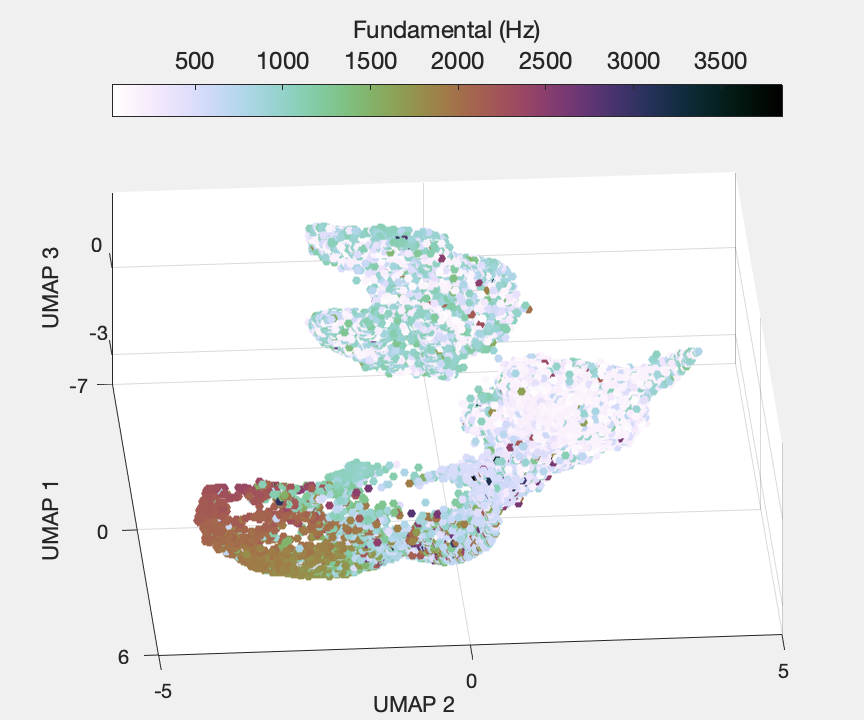

Fig10 = figure(10);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(F0_mean,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),F0_mean(MicAudioGood01), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','F0'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','F0', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
colormap(GRAD)
cc.Label.String = 'Fundamental (Hz)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig10.Units = 'inches';
Fig10.Position(3:4) = [6 5];
Fig10.PaperSize = [6 5];
print(Fig10,fullfile(Path2Paper,'SupFigure3_UMAP_Fund.pdf'),'-dpdf','-fillpage')

UMAP projection with all data color coded by BatID

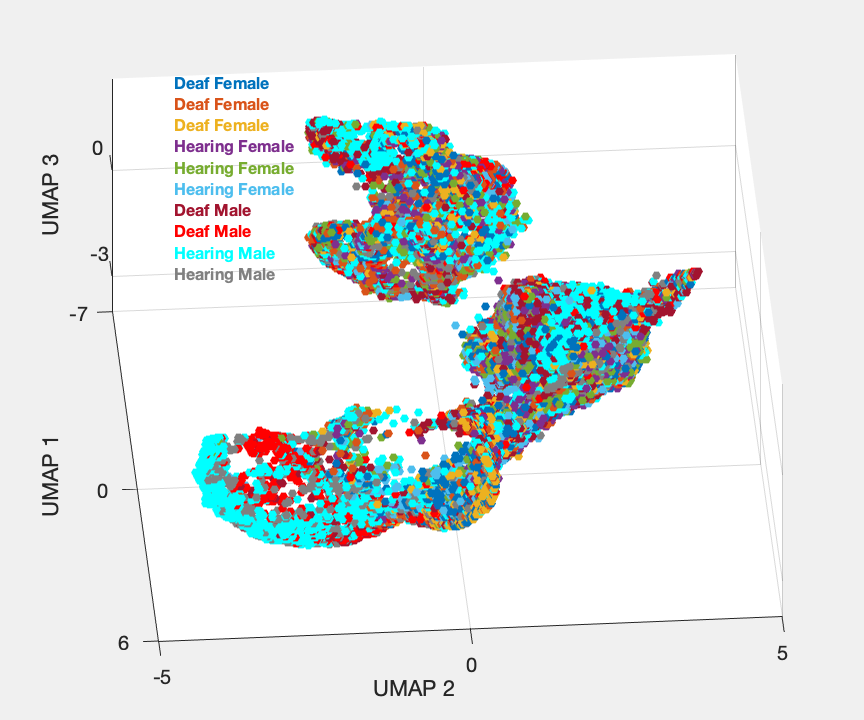

Fig11 = figure(11);
clf
set(gcf,'Visible','on')
SC3 = scatter3(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20, CBat(MicAudioGood01,:), 'filled');
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
hold on
for gg=1:length(BatSexDeaf)
    text(-7,-4, ZLim(2)-diff(ZLim)*gg/length(BatSexDeaf), sprintf('%s',BatSexDeaf{gg}), 'Color',UCBatName(gg,:), 'FontWeight','bold', 'FontSize',8 );
end

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig11.Units = 'inches';
Fig11.Position(3:4) = [6 5];
Fig11.PaperSize = [6 5];
print(Fig11,fullfile(Path2Paper,'SupFigure3_UMAP_FundBatID.pdf'),'-dpdf','-fillpage')

Plot the value of Silhouette

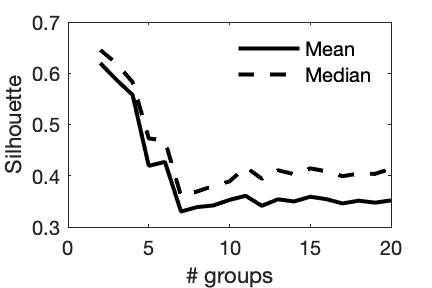

Fig12 = figure(12);
clf
set(gcf,'Visible','on')
plot(2:(length(MeanSilhouette)+1), MeanSilhouette, '-', 'LineWidth',2,'Color', 'k')
hold on
plot(2:(length(MeanSilhouette)+1), MedianSilhouette, '--', 'LineWidth',2,'Color', 'k')
legend('Mean', 'Median')
legend boxoff
ylabel('Silhouette') 
xlabel('# groups')
ylim([0.3 0.7])
yticks(0.3:0.1:0.7)
yticklabels(0.3:0.1:0.7)
Fig12.Children(1).FontSize = 10;
Fig12.Children(2).FontSize = 10;
Fig12.Units = 'inches';
Fig12.Position(3:4) = [3 2];
Fig12.PaperSize = [3 2];
print(Fig12,fullfile(Path2Paper,'SupFigure5_UMAP_Silhouette.pdf'),'-dpdf','-fillpage')

Proportion of calls for each bat in each acoustic category

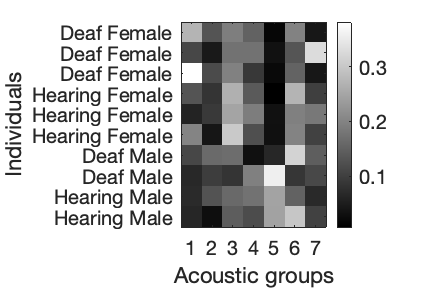

BatID_mic = BatID(MicAudioGood01);

ProbaCalls = nan(length(BatName),length(unique(TmicAll7)));
for bb=1:length(BatName)
    [N,~] = histcounts(TmicAll7(contains(BatID_mic, num2str(BatName(bb)))));
    ProbaCalls(bb,:) = N./sum(N);
end
Fig13 = figure(13);
clf
set(gcf,'Visible','on')
imagesc(ProbaCalls)
xlabel('Acoustic groups')
ylabel('Individuals')
yticks(1:length(BatName))
yticklabels(BatSexDeaf)
xticks(1:length(unique(TmicAll7)))
cc=colorbar();
colormap('gray')
cc.Ticks = 0:0.1:0.4;
Fig13.Children(1).FontSize = 10;
Fig13.Children(2).FontSize = 10;
Fig13.Units = 'inches';
Fig13.Position(3:4) = [3 2];
Fig13.PaperSize = [3 2];
print(Fig13,fullfile(Path2Paper,'SupFigure5_UMAP_VocProportion.pdf'),'-dpdf','-fillpage')

calculate the PCA of the microphone MPS for plotting purposes

% Loading previous data
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'),'MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')

%% Restrict the MPS spectral frequency to 3 cycles/kHz and normalized all
% MPS
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';

% calculate the PCA on MPS
[PC,Score,~, ~, VarExpl,~] = pca(MPS_mic_norm);

NPC90var = find(cumsum(VarExpl)>90,1);

figure()
plot(cumsum(VarExpl))
title('cumulative sum of variance explained')
xlabel('# PCs')
ylabel('Percentage')

Get the distance of each call to the closest set of 10 calls from an opposite sex individual

NumCalls=10;
SexDistance = cell(sum(MicAudioGood),1);
SexDistance_100PC = cell(sum(MicAudioGood),1);
SexDistance_3PC = cell(sum(MicAudioGood),1);
SexDistance_UMAP = cell(sum(MicAudioGood),1);
Sex_mic = Sex(MicAudioGood01);
BatID_mic = str2double(BatID(MicAudioGood01));
BatID_Pair_SexDistance = cell(sum(MicAudioGood),1);
BatID_Pair_SexDistance_100PC = cell(sum(MicAudioGood),1);
BatID_Pair_SexDistance_3PC = cell(sum(MicAudioGood),1);
BatID_Pair_SexDistance_UMAP = cell(sum(MicAudioGood),1);
DiffNeigh = 0;
parfor vv=1:sum(MicAudioGood)
    if rem(vv,1000)==0
        fprintf(1, 'Voc %d/%d\n', vv,sum(MicAudioGood))
    end
    BatID_local = BatID_mic(vv);
    Sex_local = Sex_mic{vv};
    % opposite sex targets
    BatID_targets = BatName(~contains(BatSexDeaf, Sex_local));
    % loop through targets and calculate distance to 10 closest calls
    Targets_dist = nan(size(BatID_targets));
    Targets_dist_100PC = nan(size(BatID_targets));
    Targets_dist_3PC = nan(size(BatID_targets));
    Targets_dist_UMAP = nan(size(BatID_targets));
    for tt=1:length(BatID_targets)
        Score_local = Score(vv, 1:NPC90var);
        Score_targets = Score(BatID_mic==BatID_targets(tt),1:NPC90var);
        UMAP_local = MPSmicReduction4Clustering(vv,:);
        UMAP_targets = MPSmicReduction4Clustering(BatID_mic==BatID_targets(tt),:);
        Dist_targets = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_100PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_3PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_UMAP = nan(1, sum(BatID_mic==BatID_targets(tt)));
        for ttvv=1:sum(BatID_mic==BatID_targets(tt))
            Dist_targets(ttvv) = sum((Score_local - Score_targets(ttvv,:)).^2).^0.5;
            Dist_targets_100PC(ttvv) = sum((Score_local(1:100) - Score_targets(ttvv,1:100)).^2).^0.5;
            Dist_targets_3PC(ttvv) = sum((Score_local(1:3) - Score_targets(ttvv,1:3)).^2).^0.5;
            Dist_targets_UMAP(ttvv) = sum((UMAP_local - UMAP_targets(ttvv,:)).^2).^0.5;
        end
        Dist_targets = sort(Dist_targets, 'ascend');
        Dist_targets_100PC = sort(Dist_targets_100PC, 'ascend');
        Dist_targets_3PC = sort(Dist_targets_3PC, 'ascend');
        Targets_dist(tt) = mean(Dist_targets(1:NumCalls));
        Targets_dist_100PC(tt) = mean(Dist_targets_100PC(1:NumCalls));
        Targets_dist_3PC(tt) = mean(Dist_targets_3PC(1:NumCalls));
        Dist_targets_UMAP = sort(Dist_targets_UMAP, 'ascend');
        Targets_dist_UMAP(tt) = mean(Dist_targets_UMAP(1:NumCalls));
    end
    [SexDistance{vv}, I] = min(Targets_dist);
    [SexDistance_UMAP{vv}, I_UMAP] = min(Targets_dist_UMAP);
    [SexDistance_100PC{vv}, I_100PC] = min(Targets_dist_100PC);
    [SexDistance_3PC{vv}, I_3PC] = min(Targets_dist_3PC);
    if I~=I_100PC || I~=I_UMAP || I_100PC~=I_UMAP
        DiffNeigh = DiffNeigh +1;
    end
    BatPair = sort([BatID_local BatID_targets(I)]);
    BatID_Pair_SexDistance{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_100PC)]);
    BatID_Pair_SexDistance_100PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_3PC)]);
    BatID_Pair_SexDistance_3PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_UMAP)]);
    BatID_Pair_SexDistance_UMAP{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
end

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 4).
Voc 1000/28091
Voc 8000/28091
Voc 11000/28091
Voc 4000/28091
Voc 14000/28091
Voc 7000/28091
Voc 10000/28091
Voc 3000/28091
Voc 13000/28091
Voc 6000/28091
Voc 9000/28091
Voc 2000/28091
Voc 12000/28091
Voc 5000/28091
Voc 18000/28091
Voc 16000/28091
Voc 21000/28091
Voc 19000/28091
Voc 17000/28091
Voc 15000/28091
Voc 20000/28091
Voc 23000/28091
Voc 22000/28091
Voc 24000/28091
Voc 26000/28091
Voc 25000/28091
Voc 27000/28091
Voc 28000/28091


SexDistance = cell2mat(SexDistance);
SexDistance_UMAP = cell2mat(SexDistance_UMAP);
SexDistance_100PC = cell2mat(SexDistance_100PC);
SexDistance_3PC = cell2mat(SexDistance_3PC);
fprintf(1,'%d/%d vocalizations found a different closest neighbor according to the different distance metrics\n', DiffNeigh, sum(MicAudioGood))

21719/28091 vocalizations found a different closest neighbor according to the different distance metrics


save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'SexDistance', 'SexDistance_100PC','SexDistance_3PC', 'SexDistance_UMAP','BatID_Pair_SexDistance','BatID_Pair_SexDistance_100PC','BatID_Pair_SexDistance_3PC','BatID_Pair_SexDistance_UMAP')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'SexDistance','SexDistance_100PC','SexDistance_3PC', 'SexDistance_UMAP','BatID_Pair_SexDistance','BatID_Pair_SexDistance_100PC','BatID_Pair_SexDistance_3PC','BatID_Pair_SexDistance_UMAP')

Plot the UMAP projections with color coded the distance to the closest opposite sex individual calls (distance in the PCA space)

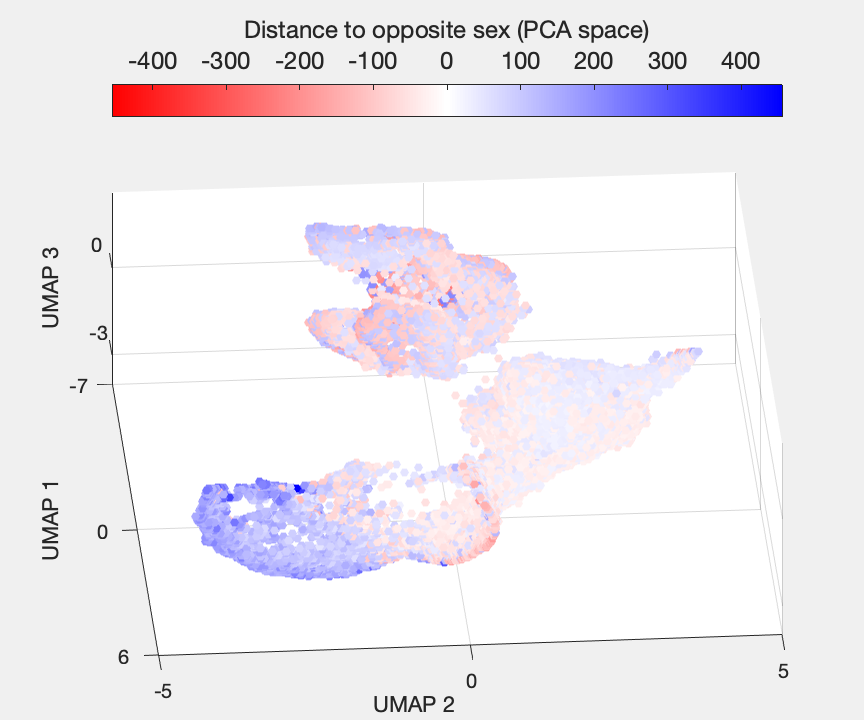

Sex_mic_sign = 2.*contains(Sex_mic, 'M') -1;
Fig11 = figure(11);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(SexDistance.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),SexDistance.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','SexDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','SexDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite sex (PCA space)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig11.Units = 'inches';
Fig11.Position(3:4) = [6 5];
Fig11.PaperSize = [6 5];
print(Fig11,fullfile(Path2Paper,'SupFigure3_UMAP_MFDistance_PCA.pdf'),'-dpdf','-fillpage')

Plot the UMAP projections with color coded the distance to the closest opposite sex individual calls (distance in the PCA space)

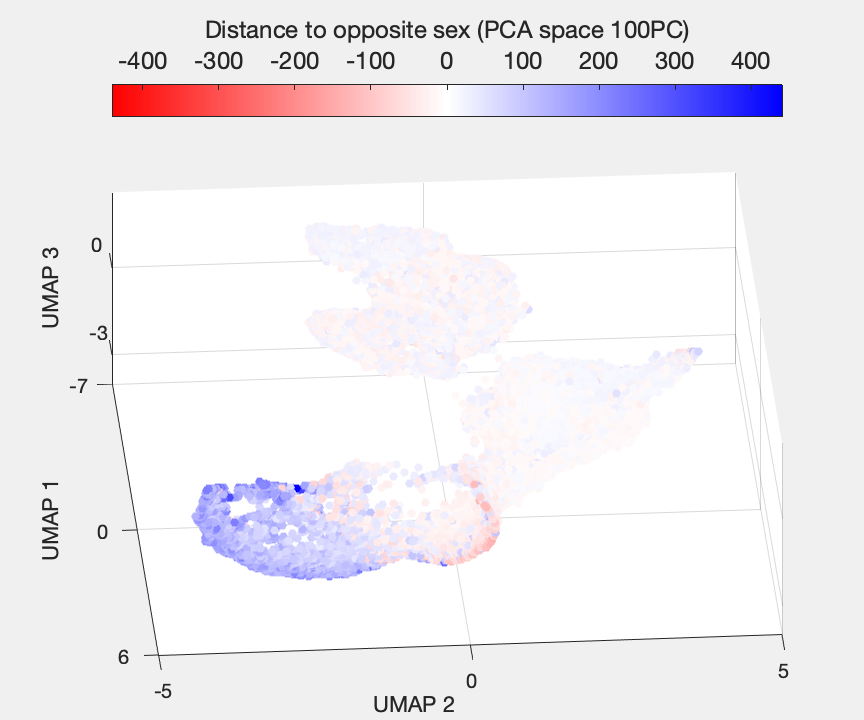

Sex_mic_sign = 2.*contains(Sex_mic, 'M') -1;
Fig11 = figure(11);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(SexDistance_100PC.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),SexDistance_100PC.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','SexDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','SexDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% caxis([-250 250])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite sex (PCA space 100PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig11.Units = 'inches';
Fig11.Position(3:4) = [6 5];
Fig11.PaperSize = [6 5];
print(Fig11,fullfile(Path2Paper,'SupFigure3_UMAP_MFDistance_PCA.pdf'),'-dpdf','-fillpage')

Plot the UMAP projections with color coded the distance to the closest opposite sex individual calls (distance in the PCA space)

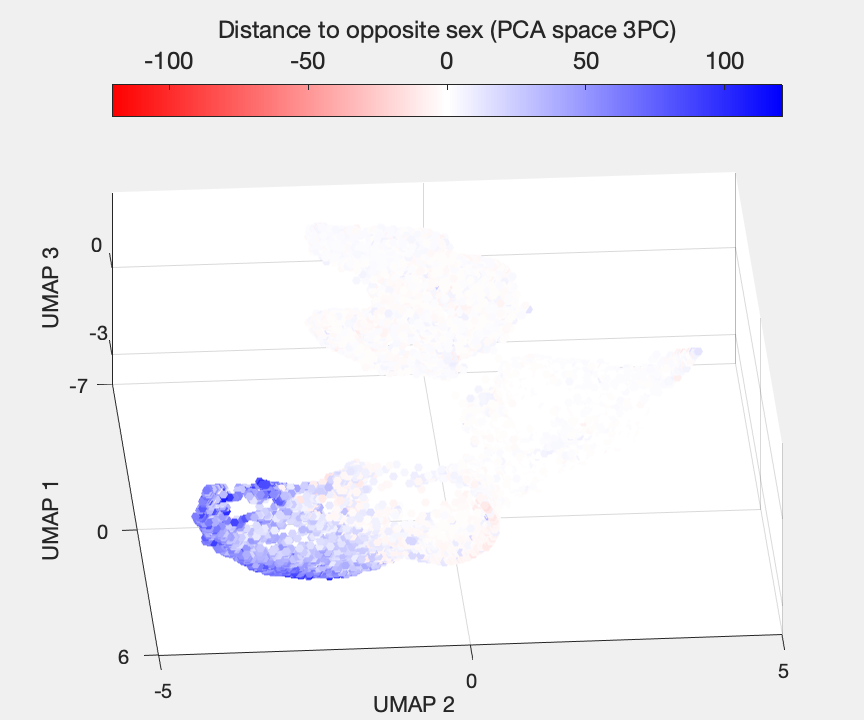

Sex_mic_sign = 2.*contains(Sex_mic, 'M') -1;
Fig11 = figure(11);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(SexDistance_3PC.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),SexDistance_3PC.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','SexDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','SexDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% caxis([-250 250])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite sex (PCA space 3PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig11.Units = 'inches';
Fig11.Position(3:4) = [6 5];
Fig11.PaperSize = [6 5];
print(Fig11,fullfile(Path2Paper,'SupFigure3_UMAP_MFDistance_PCA.pdf'),'-dpdf','-fillpage')

Plot the UMAP projections with color coded the distance to the closest opposite sex individual calls (distance in the UMAP space)

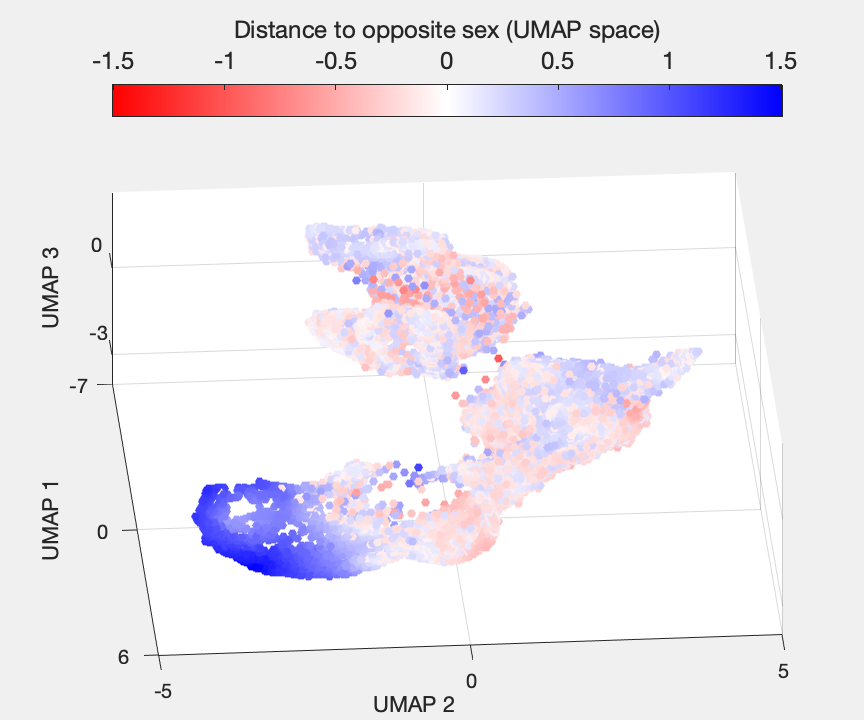

Sex_mic_sign = 2.*contains(Sex_mic, 'M') -1;
Fig12 = figure(12);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(SexDistance_UMAP.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),SexDistance_UMAP.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','SexDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','SexDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite sex (UMAP space)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig12.Units = 'inches';
Fig12.Position(3:4) = [6 5];
Fig12.PaperSize = [6 5];
print(Fig12,fullfile(Path2Paper,'SupFigure3_UMAP_MFDistance_UMAP.pdf'),'-dpdf','-fillpage')

Get the distance of each call to the closest set of 10 calls from an opposite treatment bat from the same sex

NumCalls=10;
KSDistance = cell(sum(MicAudioGood),1);
KSDistance_100PC = cell(sum(MicAudioGood),1);
KSDistance_3PC = cell(sum(MicAudioGood),1);
KSDistance_UMAP = cell(sum(MicAudioGood),1);
SexDeaf_mic = SexDeaf(MicAudioGood01);
BatID_mic = str2double(BatID(MicAudioGood01));
BatID_Pair_KSDistance = cell(sum(MicAudioGood),1);
BatID_Pair_KSDistance_100PC = cell(sum(MicAudioGood),1);
BatID_Pair_KSDistance_3PC = cell(sum(MicAudioGood),1);
BatID_Pair_KSDistance_UMAP = cell(sum(MicAudioGood),1);
DiffNeigh = 0;
parfor vv=1:sum(MicAudioGood)
    if rem(vv,1000)==0
        fprintf(1, 'Voc %d/%d\n', vv,sum(MicAudioGood))
    end
    BatID_local = BatID_mic(vv);
    SexDeaf_local = SexDeaf_mic{vv};
    % opposite treatment same sex targets
    BatID_targets = BatName(logical((~contains(BatSexDeaf, SexDeaf_local(1))).*contains(BatSexDeaf, SexDeaf_local(2))));
    % loop through targets and calculate distance to 10 closest calls
    Targets_dist = nan(size(BatID_targets));
    Targets_dist_100PC = nan(size(BatID_targets));
    Targets_dist_3PC = nan(size(BatID_targets));
    Targets_dist_UMAP = nan(size(BatID_targets));
    for tt=1:length(BatID_targets)
        Score_local = Score(vv, 1:NPC90var);
        Score_targets = Score(BatID_mic==BatID_targets(tt),1:NPC90var);
        UMAP_local = MPSmicReduction4Clustering(vv, :);
        UMAP_targets = MPSmicReduction4Clustering(BatID_mic==BatID_targets(tt),:);
        Dist_targets = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_100PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_3PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_UMAP = nan(1, sum(BatID_mic==BatID_targets(tt)));
        for ttvv=1:sum(BatID_mic==BatID_targets(tt))
            Dist_targets(ttvv) = sum((Score_local - Score_targets(ttvv,:)).^2).^0.5;
            Dist_targets_100PC(ttvv) = sum((Score_local(1:100) - Score_targets(ttvv,1:100)).^2).^0.5;
            Dist_targets_3PC(ttvv) = sum((Score_local(1:3) - Score_targets(ttvv,1:3)).^2).^0.5;
            Dist_targets_UMAP(ttvv) = sum((UMAP_local - UMAP_targets(ttvv,:)).^2).^0.5;
        end
        Dist_targets = sort(Dist_targets, 'ascend');
        Targets_dist(tt) = mean(Dist_targets(1:NumCalls));
        Dist_targets_100PC = sort(Dist_targets_100PC, 'ascend');
        Targets_dist_100PC(tt) = mean(Dist_targets_100PC(1:NumCalls));
        Dist_targets_3PC = sort(Dist_targets_3PC, 'ascend');
        Targets_dist_3PC(tt) = mean(Dist_targets_3PC(1:NumCalls));
        Dist_targets_UMAP = sort(Dist_targets_UMAP, 'ascend');
        Targets_dist_UMAP(tt) = mean(Dist_targets_UMAP(1:NumCalls));
    end
    [KSDistance{vv}, I] = min(Targets_dist);
    [KSDistance_100PC{vv}, I_100PC] = min(Targets_dist_100PC);
    [KSDistance_3PC{vv}, I_3PC] = min(Targets_dist_3PC);
    [KSDistance_UMAP{vv}, I_UMAP] = min(Targets_dist_UMAP);
    if I~=I_100PC || I~=I_UMAP || I_100PC~=I_UMAP
        DiffNeigh = DiffNeigh +1;
    end
    BatPair = sort([BatID_local BatID_targets(I)]);
    BatID_Pair_KSDistance{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_100PC)]);
    BatID_Pair_KSDistance_100PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_3PC)]);
    BatID_Pair_KSDistance_3PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_UMAP)]);
    BatID_Pair_KSDistance_UMAP{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
end

Voc 1000/28091
Voc 8000/28091
Voc 11000/28091
Voc 14000/28091
Voc 4000/28091
Voc 7000/28091
Voc 10000/28091
Voc 6000/28091
Voc 3000/28091
Voc 13000/28091
Voc 9000/28091
Voc 5000/28091
Voc 12000/28091
Voc 2000/28091
Voc 16000/28091
Voc 21000/28091
Voc 18000/28091
Voc 19000/28091
Voc 15000/28091
Voc 20000/28091
Voc 17000/28091
Voc 23000/28091
Voc 22000/28091
Voc 25000/28091
Voc 24000/28091
Voc 27000/28091
Voc 26000/28091
Voc 28000/28091


KSDistance = cell2mat(KSDistance);
KSDistance_100PC = cell2mat(KSDistance_100PC);
KSDistance_3PC = cell2mat(KSDistance_3PC);
KSDistance_UMAP = cell2mat(KSDistance_UMAP);
fprintf(1,'%d/%d vocalizations found a different closest neighbor according to the different distance metrics\n', DiffNeigh, sum(MicAudioGood))

13800/28091 vocalizations found a different closest neighbor according to the different distance metrics


save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'KSDistance','KSDistance_100PC','KSDistance_3PC','KSDistance_UMAP','BatID_Pair_KSDistance','BatID_Pair_KSDistance_100PC','BatID_Pair_KSDistance_3PC','BatID_Pair_KSDistance_UMAP')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'KSDistance','KSDistance_100PC','KSDistance_3PC','KSDistance_UMAP','BatID_Pair_KSDistance','BatID_Pair_KSDistance_100PC','BatID_Pair_KSDistance_3PC','BatID_Pair_KSDistance_UMAP')

Plot the UMAP projections with color coded the distance to the closest opposite treatment but same sex individual calls (distance in the PCA space)

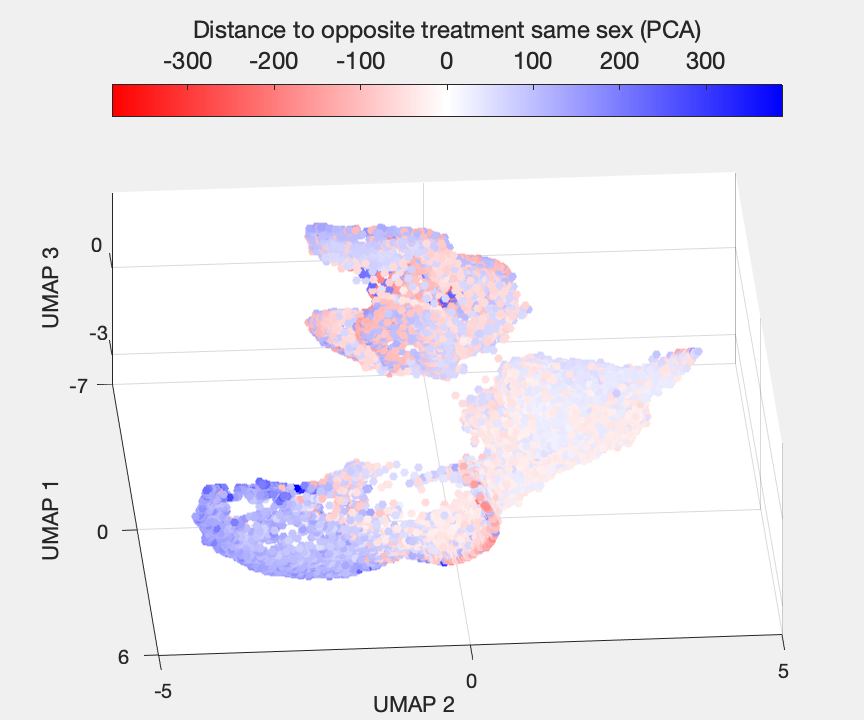

Fig13 = figure(13);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),KSDistance.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment same sex (PCA)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig13.Units = 'inches';
Fig13.Position(3:4) = [6 5];
Fig13.PaperSize = [6 5];
print(Fig13,fullfile(Path2Paper,'SupFigure3_UMAP_KSDistance_PCA.pdf'),'-dpdf','-fillpage')

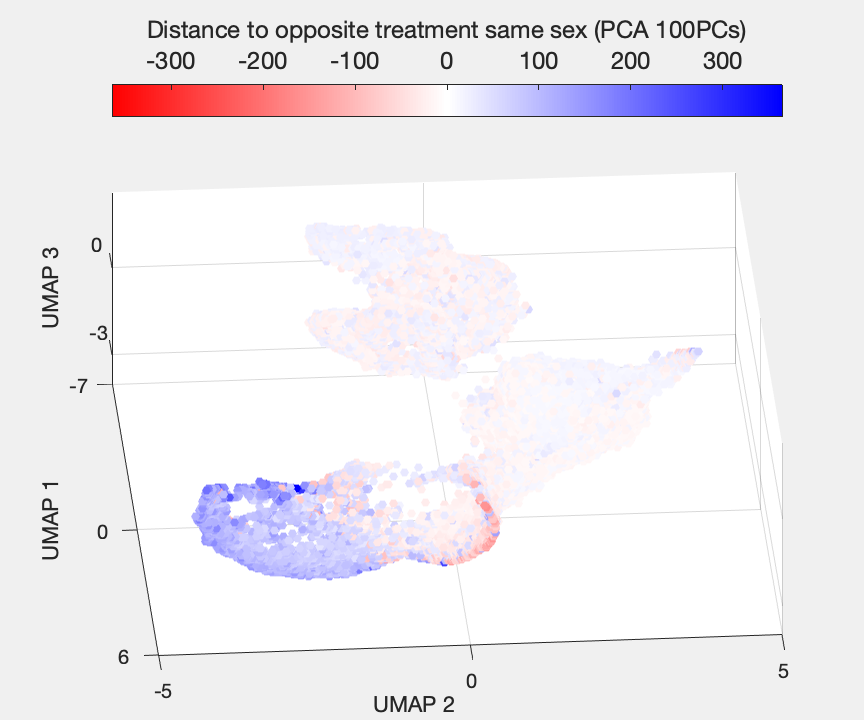

Fig13 = figure(13);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_100PC.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),KSDistance_100PC.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment same sex (PCA 100PCs)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig13.Units = 'inches';
Fig13.Position(3:4) = [6 5];
Fig13.PaperSize = [6 5];
print(Fig13,fullfile(Path2Paper,'SupFigure3_UMAP_KSDistance_PCA.pdf'),'-dpdf','-fillpage')

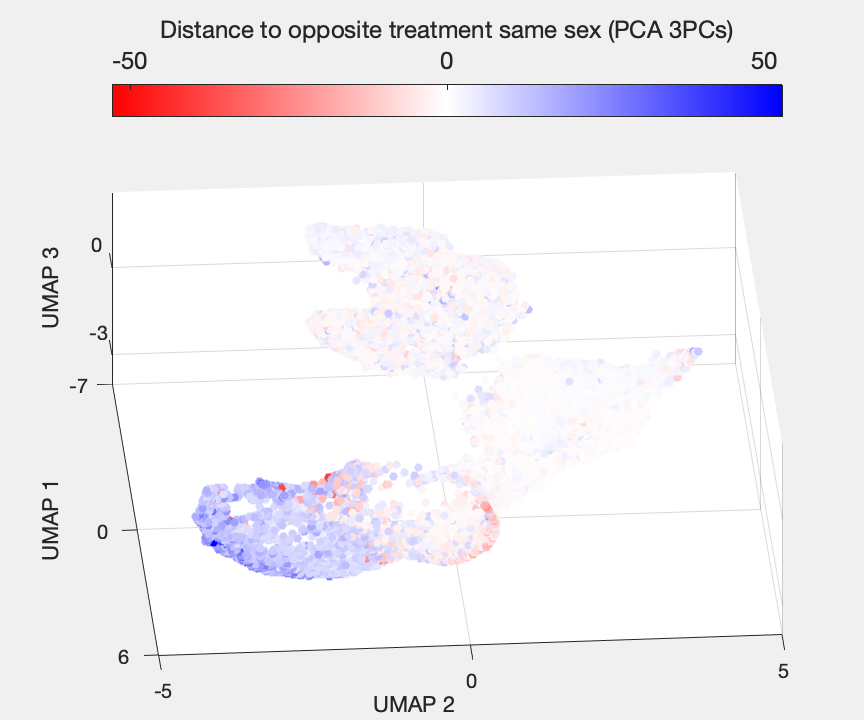

Fig13 = figure(13);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_3PC.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),KSDistance_3PC.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment same sex (PCA 3PCs)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig13.Units = 'inches';
Fig13.Position(3:4) = [6 5];
Fig13.PaperSize = [6 5];
print(Fig13,fullfile(Path2Paper,'SupFigure3_UMAP_KSDistance_PCA.pdf'),'-dpdf','-fillpage')

Plot the UMAP projections with color coded the distance to the closest opposite treatment but same sex individual calls (distance in the UMAP space)

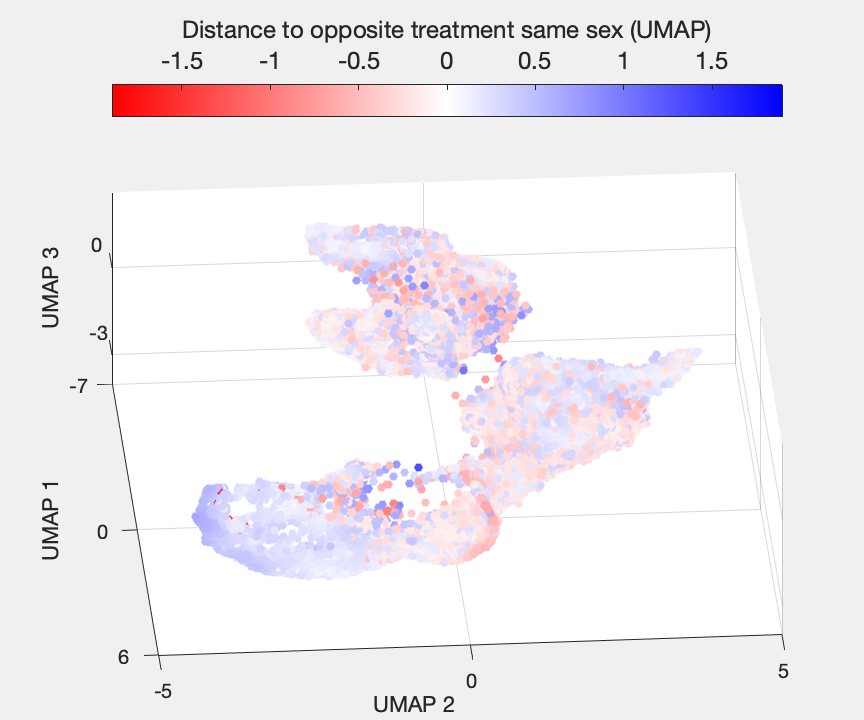

Fig14 = figure(14);
clf
set(gcf,'Visible','on')
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_UMAP.*Sex_mic_sign,x);
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),KSDistance_UMAP.*Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance_UMAP'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance_UMAP', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment same sex (UMAP)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig14.Units = 'inches';
Fig14.Position(3:4) = [6 5];
Fig14.PaperSize = [6 5];
print(Fig14,fullfile(Path2Paper,'SupFigure3_UMAP_KSDistance_UMAP.pdf'),'-dpdf','-fillpage')

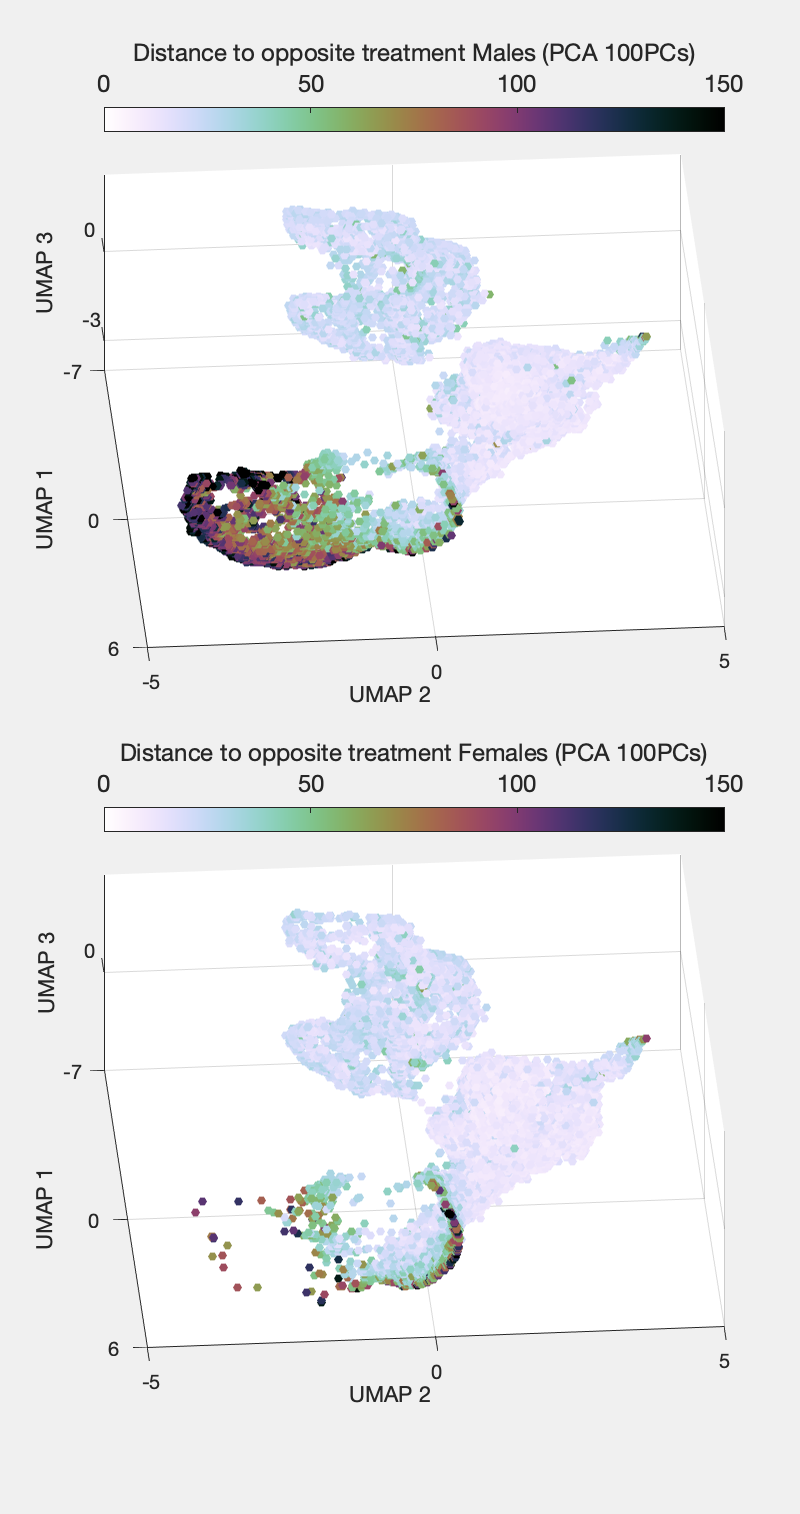

Fig15 = figure(15);
clf
set(gcf,'Visible','on')
subplot(1,2,1)
T=tiledlayout(2,1,'TileSpacing','compact');
nexttile
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_100PC(contains(Sex_mic, 'M')),x);
Tbl = table(MPSmicReduction4Clustering(contains(Sex_mic, 'M'),1),MPSmicReduction4Clustering(contains(Sex_mic, 'M'),2),MPSmicReduction4Clustering(contains(Sex_mic, 'M'),3),KSDistance_100PC(contains(Sex_mic, 'M')), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
% Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
% flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
% colormap(Cmap)
% AxisVal = caxis();
caxis([0 150])
colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment Males (PCA 100PCs)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])

nexttile
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_100PC(contains(Sex_mic, 'F')),x);
Tbl = table(MPSmicReduction4Clustering(contains(Sex_mic, 'F'),1),MPSmicReduction4Clustering(contains(Sex_mic, 'F'),2),MPSmicReduction4Clustering(contains(Sex_mic, 'F'),3),KSDistance_100PC(contains(Sex_mic, 'F')), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
% Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
% flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
% colormap(Cmap)
% AxisVal = caxis();
caxis([0 150])
colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment Females (PCA 100PCs)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])


% Fig15.Units = 'inches';
% Fig15.Position(3:4) = [6 5];
% Fig15.PaperSize = [6 5];
% print(Fig15,fullfile(Path2Paper,'SupFigure3_UMAP_KSDistance_PCA_MF.pdf'),'-dpdf','-fillpage')

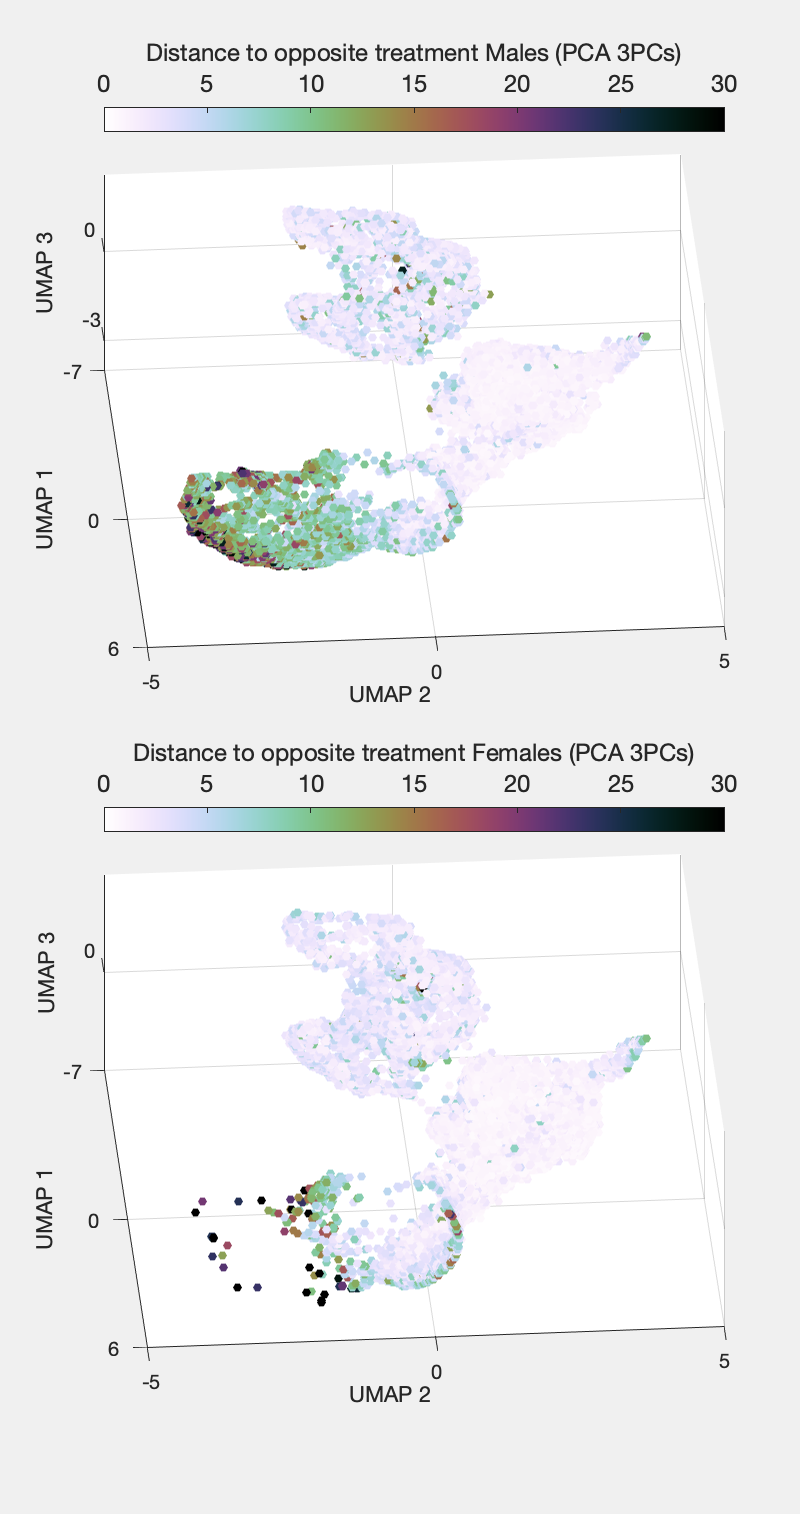

Fig15 = figure(15);
clf
set(gcf,'Visible','on')
subplot(1,2,1)
T=tiledlayout(2,1,'TileSpacing','compact');
nexttile
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_3PC(contains(Sex_mic, 'M')),x);
Tbl = table(MPSmicReduction4Clustering(contains(Sex_mic, 'M'),1),MPSmicReduction4Clustering(contains(Sex_mic, 'M'),2),MPSmicReduction4Clustering(contains(Sex_mic, 'M'),3),KSDistance_3PC(contains(Sex_mic, 'M')), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
% Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
% flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
% colormap(Cmap)
% AxisVal = caxis();
caxis([0 30])
colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment Males (PCA 3PCs)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])

nexttile
x=1;
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(KSDistance_3PC(contains(Sex_mic, 'F')),x);
Tbl = table(MPSmicReduction4Clustering(contains(Sex_mic, 'F'),1),MPSmicReduction4Clustering(contains(Sex_mic, 'F'),2),MPSmicReduction4Clustering(contains(Sex_mic, 'F'),3),KSDistance_3PC(contains(Sex_mic, 'F')), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
% Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
% flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
% colormap(Cmap)
% AxisVal = caxis();
caxis([0 30])
colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment Females (PCA 3PCs)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

% XLim = get(gca, 'XLim');
% XLim = [floor(XLim(1)) ceil(XLim(2))];
XLim = [-7 6];
set(gca, 'XLim', XLim);
% YLim = get(gca, 'YLim');
% YLim = [-5 ceil(YLim(2))];
YLim = [-5 5];
set(gca, 'YLim', YLim);
% ZLim = get(gca, 'ZLim');
% ZLim = [floor(ZLim(1)) ceil(ZLim(2))];
ZLim = [-3 3];
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])


% Fig15.Units = 'inches';
% Fig15.Position(3:4) = [6 5];
% Fig15.PaperSize = [6 5];
% print(Fig15,fullfile(Path2Paper,'SupFigure3_UMAP_KSDistance_PCA_MF.pdf'),'-dpdf','-fillpage')

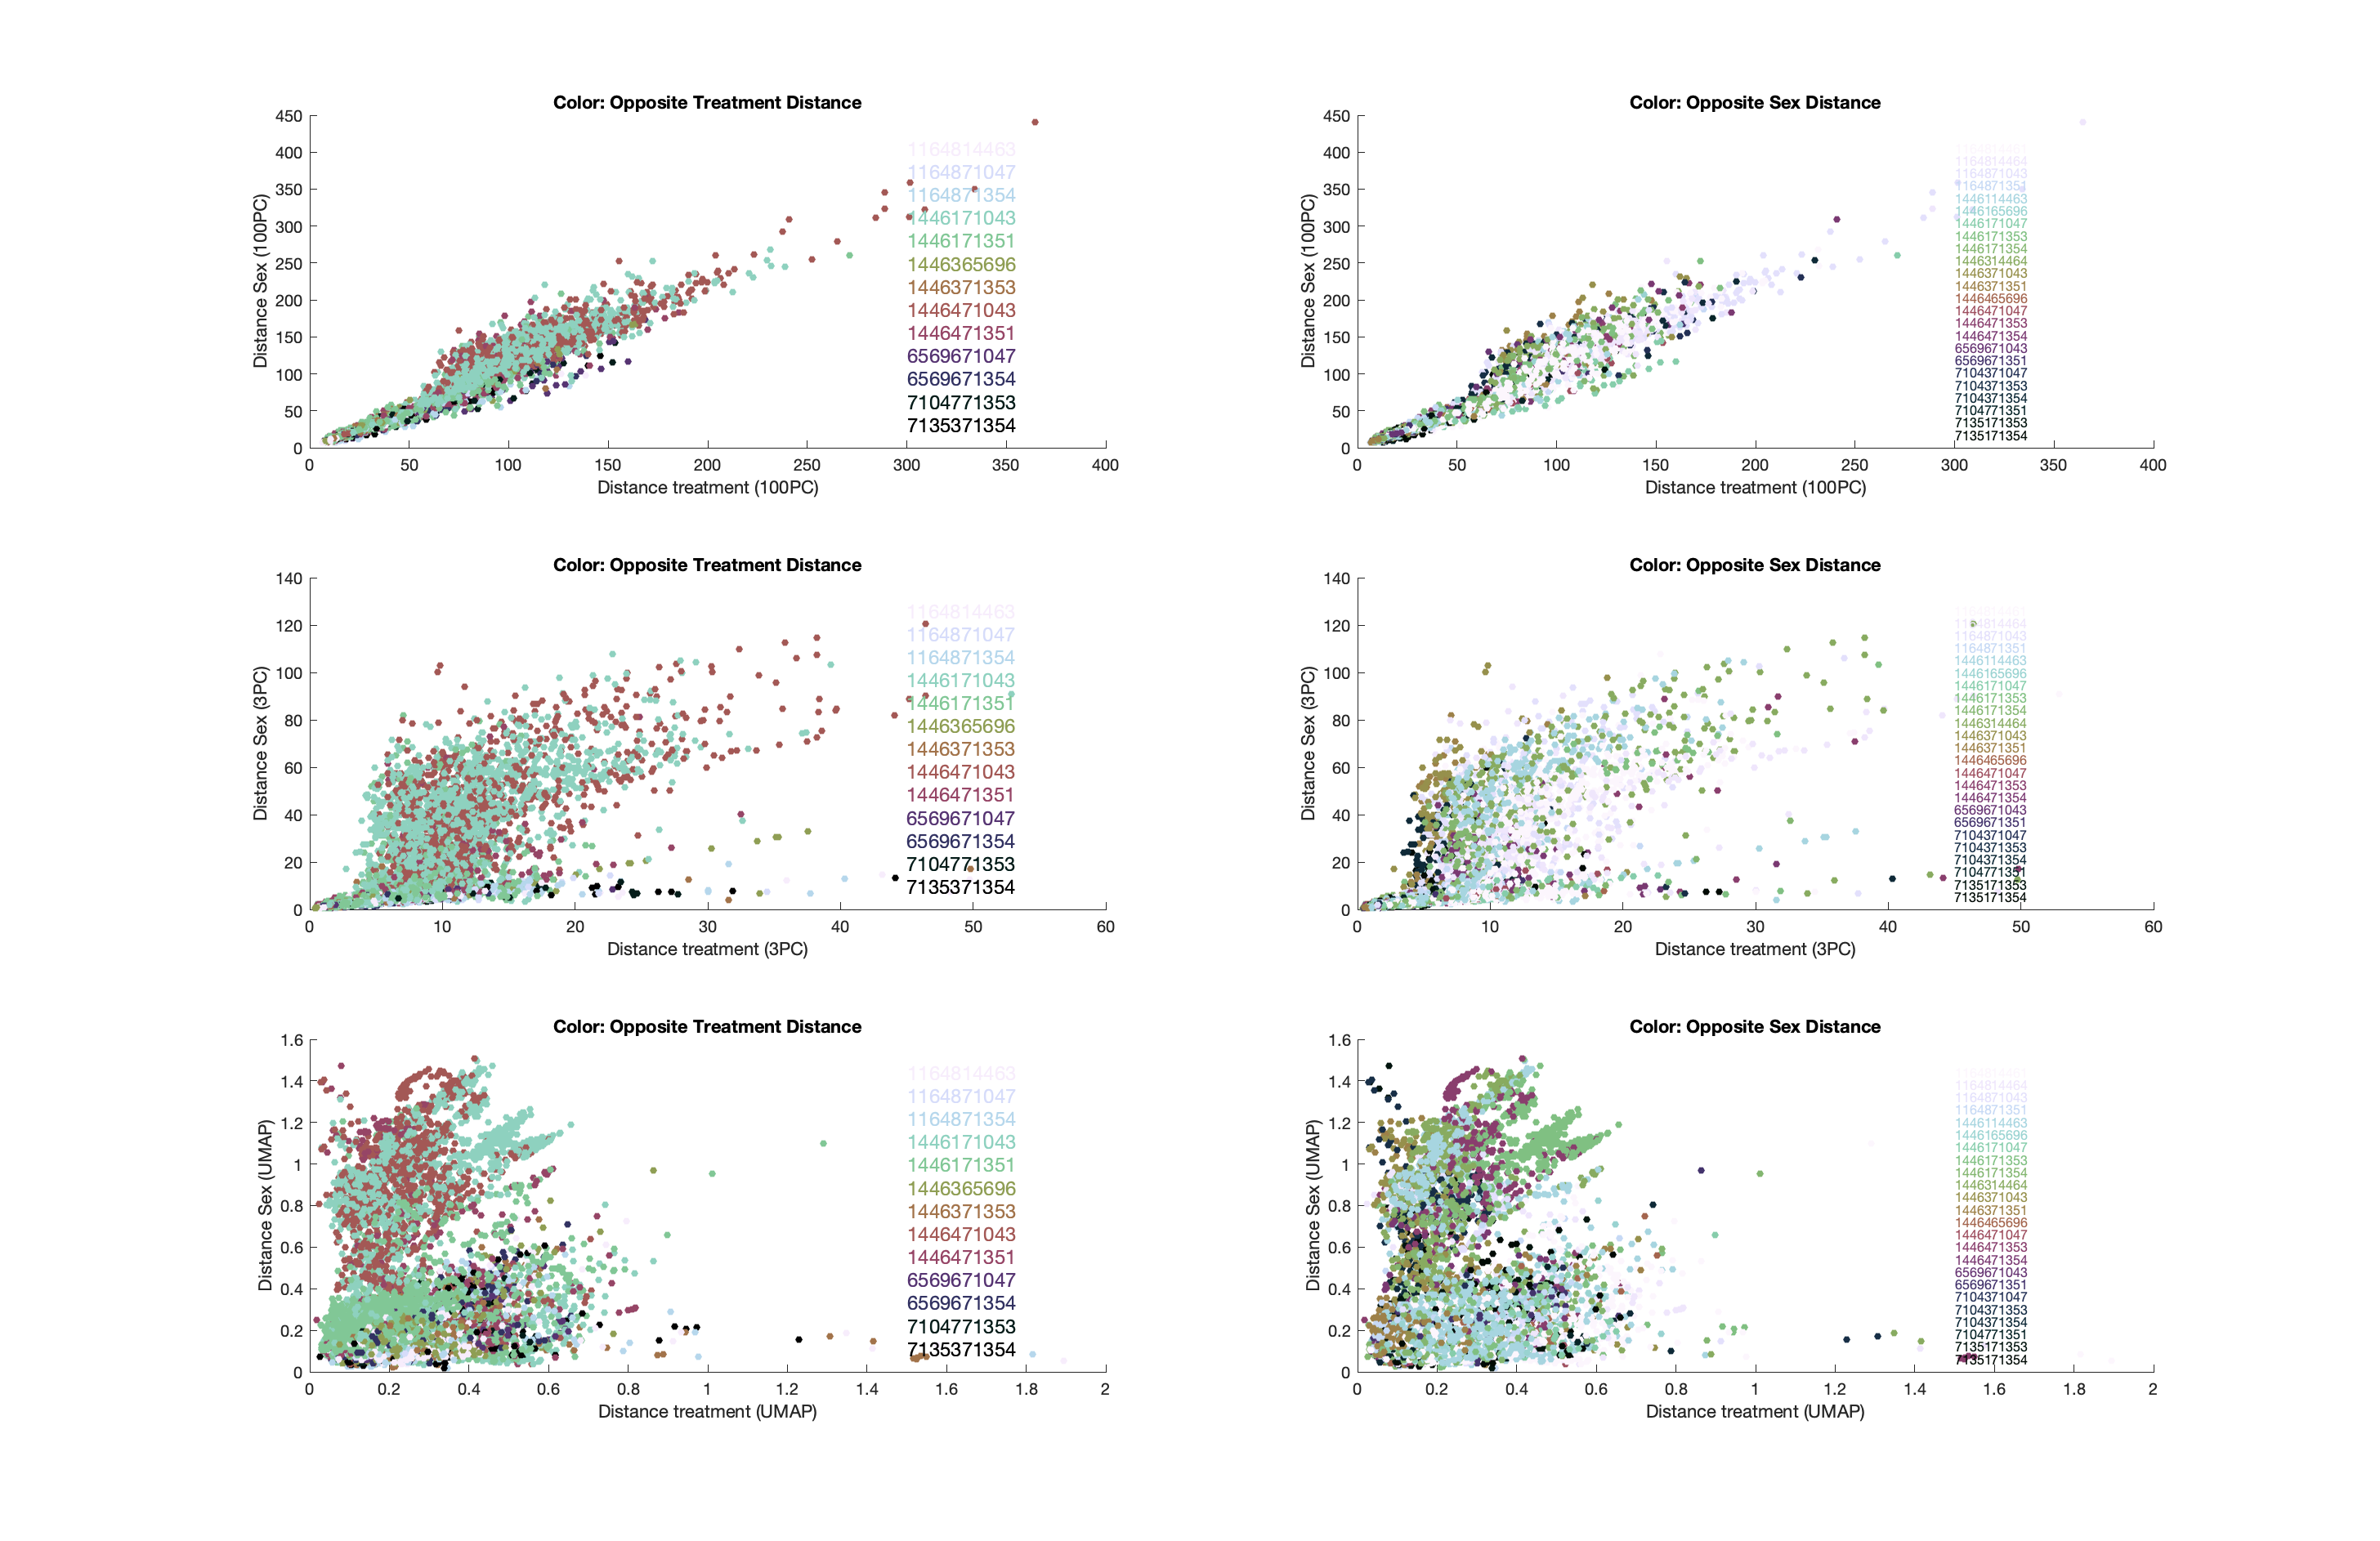

UPair = cell(1,6);
UPair{1} = unique(BatID_Pair_KSDistance_100PC)';
UPair{2} = unique(BatID_Pair_SexDistance_100PC)';
UPair{3} = unique(BatID_Pair_KSDistance_3PC)';
UPair{4} = unique(BatID_Pair_SexDistance_3PC)';
UPair{5} = unique(BatID_Pair_KSDistance_UMAP)';
UPair{6} = unique(BatID_Pair_SexDistance_UMAP)';
UPairall = unique([UPair{:}]);
[Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(1:length(UPairall),1);

Fig16 = figure(16);
clf
set(gcf,'Visible','on')
subplot(3,2,1)
ColPair = nan(NVoc,3);
for pp=1:length(UPair{1})
    LocalCol = Colors(strcmp(UPairall, UPair{1}{pp}),:);
    ColPair(strcmp(BatID_Pair_KSDistance_100PC,UPair{1}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_KSDistance_100PC,UPair{1}{pp})),1);
end

scatter(KSDistance_100PC, SexDistance_100PC, 20, ColPair, 'filled');
title('Color: Opposite Treatment Distance')
ylabel('Distance Sex (100PC)'); xlabel('Distance treatment (100PC)')
XLim = xlim();
YLim = ylim();
for pp=1:length(UPair{1})
    LocalCol = Colors(strcmp(UPairall, UPair{1}{pp}),:);
    hold on
    text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{1})*(pp-1), UPair{1}{pp},'Color', LocalCol, 'FontSize',12)
end
hold off

subplot(3,2,2)
ColPair = nan(NVoc,3);
for pp=1:length(UPair{2})
    LocalCol = Colors(strcmp(UPairall, UPair{2}{pp}),:);
    ColPair(strcmp(BatID_Pair_SexDistance_100PC,UPair{2}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_SexDistance_100PC,UPair{2}{pp})),1);
end
scatter(KSDistance_100PC, SexDistance_100PC, 20, ColPair, 'filled');
title('Color: Opposite Sex Distance')
ylabel('Distance Sex (100PC)'); xlabel('Distance treatment (100PC)')
XLim = xlim();
YLim = ylim();
for pp=1:length(UPair{2})
    LocalCol = Colors(strcmp(UPairall, UPair{2}{pp}),:);
    hold on
    text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{2})*(pp-1), UPair{2}{pp},'Color', LocalCol, 'FontSize',8)
end
hold off

subplot(3,2,3)
ColPair = nan(NVoc,3);
for pp=1:length(UPair{3})
    LocalCol = Colors(strcmp(UPairall, UPair{3}{pp}),:);
    ColPair(strcmp(BatID_Pair_KSDistance_3PC,UPair{3}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_KSDistance_3PC,UPair{3}{pp})),1);
end
scatter(KSDistance_3PC, SexDistance_3PC, 20, ColPair, 'filled');
title('Color: Opposite Treatment Distance')
ylabel('Distance Sex (3PC)'); xlabel('Distance treatment (3PC)')
XLim = xlim();
YLim = ylim();
for pp=1:length(UPair{3})
    LocalCol = Colors(strcmp(UPairall, UPair{3}{pp}),:);
    hold on
    text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{3})*(pp-1), UPair{3}{pp},'Color', LocalCol, 'FontSize',12)
end
hold off

subplot(3,2,4)
ColPair = nan(NVoc,3);
for pp=1:length(UPair{4})
    LocalCol = Colors(strcmp(UPairall, UPair{4}{pp}),:);
    ColPair(strcmp(BatID_Pair_SexDistance_3PC,UPair{4}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_SexDistance_3PC,UPair{4}{pp})),1);
end
scatter(KSDistance_3PC, SexDistance_3PC, 20, ColPair, 'filled');
title('Color: Opposite Sex Distance')
ylabel('Distance Sex (3PC)'); xlabel('Distance treatment (3PC)')
XLim = xlim();
YLim = ylim();
for pp=1:length(UPair{4})
    LocalCol = Colors(strcmp(UPairall, UPair{4}{pp}),:);
    hold on
    text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{4})*(pp-1), UPair{4}{pp},'Color', LocalCol, 'FontSize',8)
end
hold off

subplot(3,2,5)
ColPair = nan(NVoc,3);
for pp=1:length(UPair{5})
    LocalCol = Colors(strcmp(UPairall, UPair{5}{pp}),:);
    ColPair(strcmp(BatID_Pair_KSDistance_UMAP,UPair{5}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_KSDistance_UMAP,UPair{5}{pp})),1);
end
scatter(KSDistance_UMAP, SexDistance_UMAP, 20, ColPair, 'filled');
title('Color: Opposite Treatment Distance')
ylabel('Distance Sex (UMAP)'); xlabel('Distance treatment (UMAP)')
XLim = xlim();
YLim = ylim();
for pp=1:length(UPair{5})
    LocalCol = Colors(strcmp(UPairall, UPair{5}{pp}),:);
    hold on
    text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{5})*(pp-1), UPair{5}{pp},'Color', LocalCol, 'FontSize',12)
end
hold off

subplot(3,2,6)
ColPair = nan(NVoc,3);
for pp=1:length(UPair{6})
    LocalCol = Colors(strcmp(UPairall, UPair{6}{pp}),:);
    ColPair(strcmp(BatID_Pair_SexDistance_UMAP,UPair{6}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_SexDistance_UMAP,UPair{6}{pp})),1);
end
scatter(KSDistance_UMAP, SexDistance_UMAP, 20, ColPair, 'filled');
title('Color: Opposite Sex Distance')
ylabel('Distance Sex (UMAP)'); xlabel('Distance treatment (UMAP)')
XLim = xlim();
YLim = ylim();
for pp=1:length(UPair{6})
    LocalCol = Colors(strcmp(UPairall, UPair{6}{pp}),:);
    hold on
    text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{6})*(pp-1), UPair{6}{pp},'Color', LocalCol, 'FontSize',8)
end
hold off

Look if for each subject the calls that are the most sexually dimorphics are also the one that are the most affected by treatment

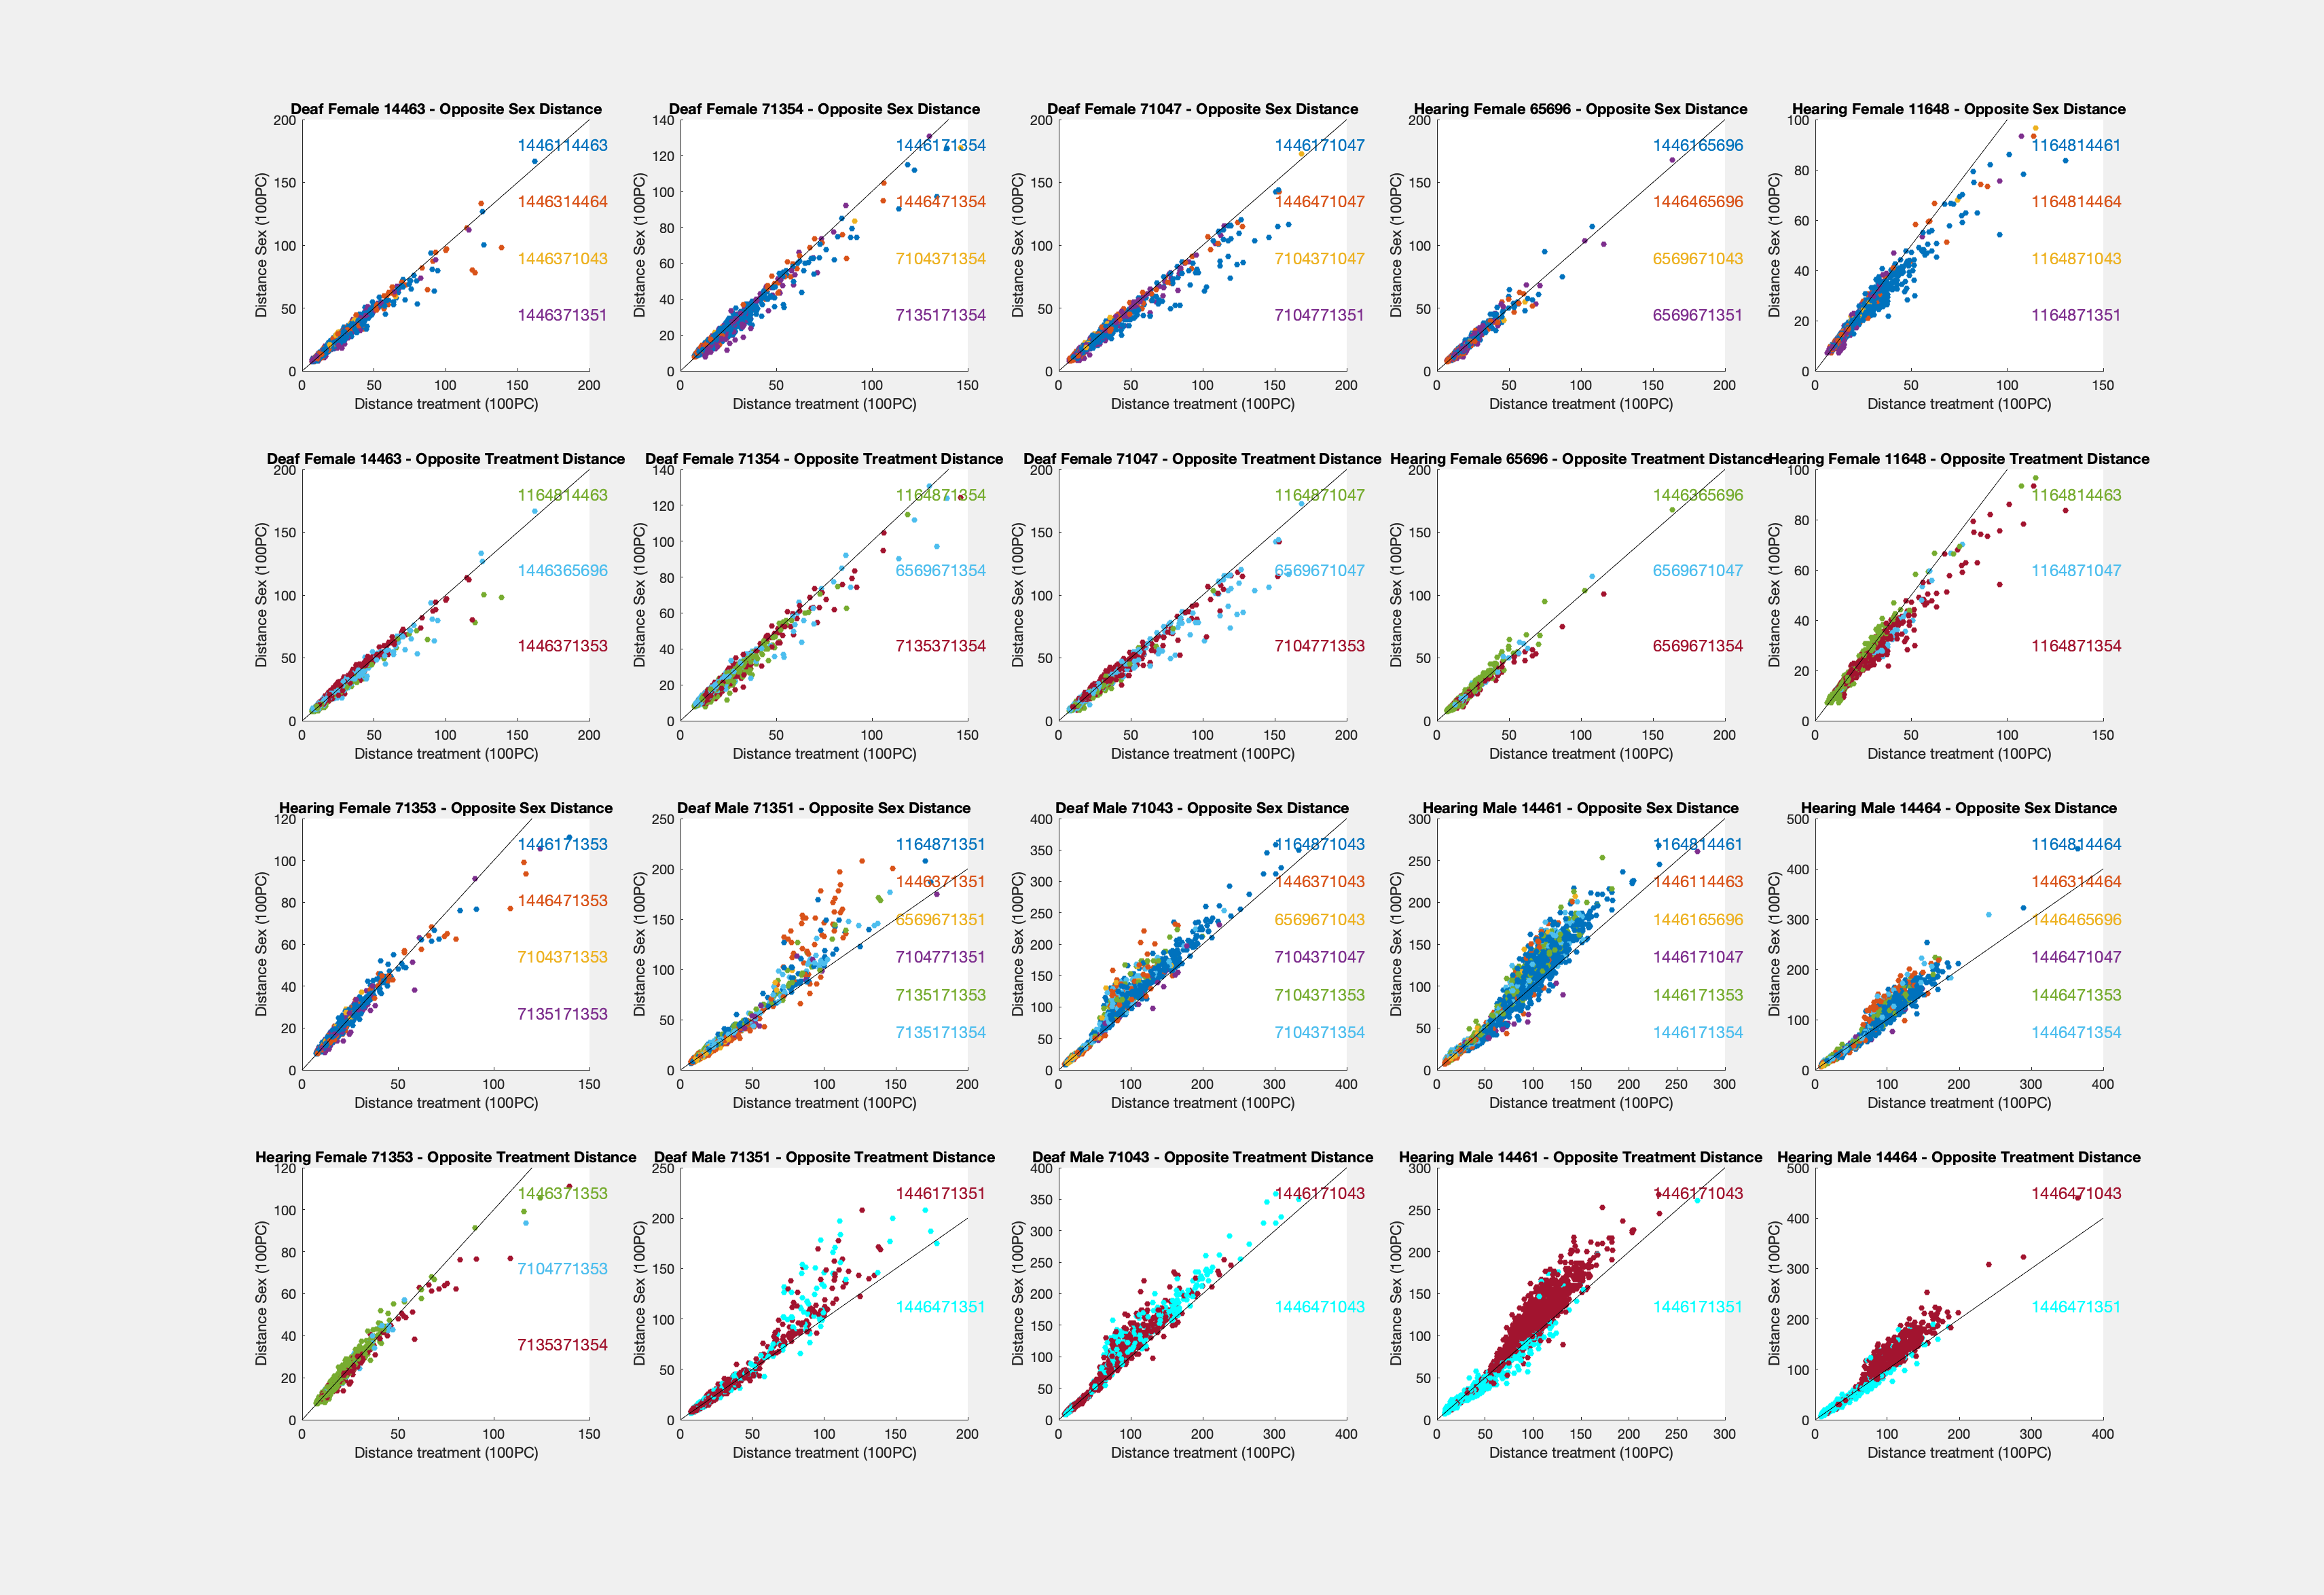

figure(17)
clf
set(gcf,'Visible','on')
CSD = [1:5 11:15];
CTD = [6:10 16:20];
UPair = cell(1,2);
for bb=1:length(BatName)
    IndBat = BatID_mic==BatName(bb);
    UPair{2} = unique(BatID_Pair_KSDistance_100PC(IndBat))';
    UPair{1} = unique(BatID_Pair_SexDistance_100PC(IndBat))';
    UPairall = [UPair{:}];

    subplot(4,5,CSD(bb))
    ColPair = nan(sum(IndBat),3);
    for pp=1:length(UPair{1})
        LocalCol = ColorCode(strcmp(UPairall, UPair{1}{pp}),:);
        ColPair(strcmp(BatID_Pair_SexDistance_100PC(IndBat),UPair{1}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_SexDistance_100PC(IndBat),UPair{1}{pp})),1);
    end
    scatter(KSDistance_100PC(IndBat), SexDistance_100PC(IndBat), 20, ColPair, 'filled');
    title(sprintf('%s %d - Opposite Sex Distance', BatSexDeaf{bb}, BatName(bb)))
    ylabel('Distance Sex (100PC)'); xlabel('Distance treatment (100PC)')
    XLim = xlim();
    YLim = ylim();
    for pp=1:length(UPair{1})
        LocalCol = ColorCode(strcmp(UPairall, UPair{1}{pp}),:);
        hold on
        text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{1})*(pp-1), UPair{1}{pp},'Color', LocalCol, 'FontSize',12)
    end
    plot([0 min(XLim(2), YLim(2))], [0 min(XLim(2), YLim(2))], '-k')
    hold off

    subplot(4,5,CTD(bb))
    ColPair = nan(sum(IndBat),3);
    for pp=1:length(UPair{2})
        LocalCol = ColorCode(strcmp(UPairall, UPair{2}{pp}),:);
        ColPair(strcmp(BatID_Pair_KSDistance_100PC(IndBat),UPair{2}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_KSDistance_100PC(IndBat),UPair{2}{pp})),1);
    end
    scatter(KSDistance_100PC(IndBat), SexDistance_100PC(IndBat), 20, ColPair, 'filled');
    title(sprintf('%s %d - Opposite Treatment Distance', BatSexDeaf{bb},BatName(bb)))
    ylabel('Distance Sex (100PC)'); xlabel('Distance treatment (100PC)')
    XLim = xlim();
    YLim = ylim();
    for pp=1:length(UPair{2})
        LocalCol = ColorCode(strcmp(UPairall, UPair{2}{pp}),:);
        hold on
        text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{2})*(pp-1), UPair{2}{pp},'Color', LocalCol, 'FontSize',12)
    end
    plot([0 min(XLim(2), YLim(2))], [0 min(XLim(2), YLim(2))], '-k')
    hold off
end

figure(18)
clf
set(gcf,'Visible','on')
CSD = [1:5 11:15];
CTD = [6:10 16:20];
UPair = cell(1,2);
for bb=1:length(BatName)
    IndBat = BatID_mic==BatName(bb);
    UPair{2} = unique(BatID_Pair_KSDistance_3PC(IndBat))';
    UPair{1} = unique(BatID_Pair_SexDistance_3PC(IndBat))';
    UPairall = [UPair{:}];

    subplot(4,5,CSD(bb))
    ColPair = nan(sum(IndBat),3);
    for pp=1:length(UPair{1})
        LocalCol = ColorCode(strcmp(UPairall, UPair{1}{pp}),:);
        ColPair(strcmp(BatID_Pair_SexDistance_3PC(IndBat),UPair{1}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_SexDistance_3PC(IndBat),UPair{1}{pp})),1);
    end
    scatter(KSDistance_3PC(IndBat), SexDistance_3PC(IndBat), 20, ColPair, 'filled');
    title(sprintf('%s %d - Opposite Sex Distance', BatSexDeaf{bb}, BatName(bb)))
    ylabel('Distance Sex (3PC)'); xlabel('Distance treatment (3PC)')
    XLim = xlim();
    YLim = ylim();
    for pp=1:length(UPair{1})
        LocalCol = ColorCode(strcmp(UPairall, UPair{1}{pp}),:);
        hold on
        text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{1})*(pp-1), UPair{1}{pp},'Color', LocalCol, 'FontSize',12)
    end
    plot([0 min(XLim(2), YLim(2))], [0 min(XLim(2), YLim(2))], '-k')
    hold off

    subplot(4,5,CTD(bb))
    ColPair = nan(sum(IndBat),3);
    for pp=1:length(UPair{2})
        LocalCol = ColorCode(strcmp(UPairall, UPair{2}{pp}),:);
        ColPair(strcmp(BatID_Pair_KSDistance_100PC(IndBat),UPair{2}{pp}),:) = repmat(LocalCol,sum(strcmp(BatID_Pair_KSDistance_100PC(IndBat),UPair{2}{pp})),1);
    end
    scatter(KSDistance_3PC(IndBat), SexDistance_3PC(IndBat), 20, ColPair, 'filled');
    title(sprintf('%s %d - Opposite Treatment Distance', BatSexDeaf{bb},BatName(bb)))
    ylabel('Distance Sex (3PC)'); xlabel('Distance treatment (3PC)')
    XLim = xlim();
    YLim = ylim();
    for pp=1:length(UPair{2})
        LocalCol = ColorCode(strcmp(UPairall, UPair{2}{pp}),:);
        hold on
        text(XLim(2)*0.75, YLim(2)*0.9 - YLim(2)*0.9/length(UPair{2})*(pp-1), UPair{2}{pp},'Color', LocalCol, 'FontSize',12)
    end
    plot([0 min(XLim(2), YLim(2))], [0 min(XLim(2), YLim(2))], '-k')
    hold off
end

function [Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(VARcol,x, MinColVal, MaxColVal)
    % Getting VARZ ready for plotting.
    % If VARcol is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARcol by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<2
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<3
        MinColVal=0;
    end

    if nargin<4
        MaxColVal = max(VARcol);
    end

%     if nargin<5
%         LogToggle=0;
%     end
    % Make sure you don't have nan values
    VARcol = VARcol(~isnan(VARcol));
%     if LogToggle==2
%         VARcol = log2(VARcol);
%     elseif LogToggle==10
%         VARcol = log10(VARcol);
%     end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcol<=0)>0
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal==1
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal
        Slide = -MinColVal+ 10^(-x);
    end

    VARcol_cube = ceil((VARcol+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
    GRAD=cubehelix(ceil((MaxColVal+Slide)*10^x),0.5, -1.5, 1, 1, [1,0]);

    NU = length(VARcol_cube); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    for jj=1:NU
        Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
    end
    
% figure()
%     
%     cc=colorbar();
%     colormap(GRAD)
%     set(gca, 'Color', [0.7 0.7 0.7])
%     
%     YTL = get(cc, 'YTickLabel');
%     YTL_new = ceil((MaxColVal+Slide)*10^x) .* str2double(YTL)/10^x - Slide;
%     if LogToggle==2
%         YTL_new = 2.^YTL_new;
%     elseif LogToggle==10
%         YTL_new = 10.^YTL_new;
%     end
%     YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
%     set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end

function scatter_cubehelix(VAR, VARcol,x, MinColVal, LogToggle)
    % Getting VARZ ready for plotting.
    % Let's say you want to plot VARX VARY VARZ. If VARZ is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARY by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<3
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<4
        MinColVal=0;
    end

    if nargin<5
        LogToggle=0;
    end
    % Make sure you don't have nan values
    VAR = VAR(~isnan(VARcol), :);
    VARcol = VARcol(~isnan(VARcol));
    if LogToggle==2
        VARcol = log2(VARcol);
    elseif LogToggle==10
        VARcol = log10(VARcol);
    end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcol<=0)>0
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal
        Slide = -min(VARcol)+ 10^(-x);
    end

    
    
    VARcol_cube = ceil((VARcol+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
    GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);

    NU = length(VARcol_cube); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    for jj=1:NU
        Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
    end
    
    figure()
    scatter3(VAR(:,1), VAR(:,2),VAR(:,3),20,Colors,'filled')
    xlabel('Dim1')
    ylabel('Dim2')
    zlabel('Dim3')
    cc=colorbar();
    colormap(GRAD)
    set(gca, 'Color', [0.7 0.7 0.7])
    
    YTL = get(cc, 'YTickLabel');
    YTL_new = max(VARcol_cube) .* str2double(YTL)/10^x - Slide;
    if LogToggle==2
        YTL_new = 2.^YTL_new;
    elseif LogToggle==10
        YTL_new = 10.^YTL_new;
    end
    YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
    set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end